Irene Celestino - Daniele Poidomani 

16/11/2021

# Logbook - Prima Parte

## Es. 1 - Costruzione circuito

Abbiamo costruito il circuito, usando come resistenza del Gain Rg=1 kOhm e come resistenza del Source Rs=10 Ohm. Abbiamo preso per Rs la resistenza più bassa possibile, perché le correnti che scorrono nel circuito devono essere sotto 10 mA per non danneggiare la scheda National. 

## Es. 2 - Tensione di Soglia del MOSFET

Abbiamo collegato l'amperometro per misurare la corrente che scorre nel transistor (messo tra l'analog output CB21 e il drain). 

Abbiamo impostato con Vin_Vout_2C.vi per prima cosa Vdrain a 0.1 V. Misurando Vdrain con il multimetro si ottiene $0.999 \pm$ V.

Abbiamo poi cambiato Vgate (CB22) e misurato la corrente con l'amperometro e Vs (CB33):

- $V_g = 0.999 \pm 0.007$ V : $I = 0$ A  - $V_s = 0$ V

- $V_g=1.498 \pm 0.007$ V:  $I = 0.06 \pm 0.02 \mu$A - $V_s = 0$ V

- $V_g= 1.717 \pm 0.007$ V : $I=1.0 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.800 \pm 0.007$ V : $I=2.9 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.898 \pm 0.006$ V : $I = 9.8 \pm 0.1 \mu$A - $V_s= 0.22 \pm 0.08$ mV

- $V_g = 1.998 \pm 0.007$ V : $I = 32.97 \pm 0.04\mu$A - $V_s= 0.49 \pm 0.06$ mV

- $V_g=2.995 \pm 0.007$ V : $I= 4.05\pm 0.05$ mA - $V_s= 45.74 \pm 0.14$ mV 

- $V_g=3.994 \pm 0.007$ V :  $I= 4.880 \pm 0.004$ mA - $V_s= 52.04 \pm 0.09$ mV

Si può quindi stimare che $V_T$ è intorno ai 2 V, in accordo con il valore tipico riportato dal datasheet, 2.1 V

## Es. 3 - Corrente del Gain

Abbiamo collegato l'amperometro il serie alla resistenza del Gain (tra Rg e CB22) e misurato la corrente che scorre in Rg, variando Vg con Vin_Vout_2C.vi

Viene sempre una corrente di 0 A: il valore massimo misurato è $1.00 \pm 0.06 \mu$A per Vg = 4 V. 

Avevamo verificato che non scorresse corrente anche nell'esercizio precedente: abbiamo messo CB68 tra la resistenza e il Gain e la tensione che si misura lì è sempre compatibile con quella impostata nel vi, quindi non c'è caduta di tensione ai capi di Rg.

## Es. 4 e 5 - Aggiunta dell'OpAmp

La corrente $I_{DS}$ non entra nell'ingresso invertente dell'OpAmp, ma scorre nella resistenza di feeedback e poi entra nell'OpAmp dall'uscita. Ci serve quindi un OpAmp con una resistenza di ingresso molto alta, o almeno molto maggiore di Rtran. 

Abbiamo usato uA741C, in modo da lavorare in un range ampio di tensioni, tra -12 e 12 V, nonostante abbia una resistenza di ingresso più bassa di altri modelli a nostra disposizione. 

Abbiamo scelto Rtrans = 100 Ohm, di vari ordini di grandezza inferiore a quella dell'OpAmp, dell'ordine di 0.3-2 MOhm. 

## Es. 6 - Corrente di Drain VS Tensione di Drain

Abbiamo usato FET_vs_DRAIN.vi per misurare la curva $I_{DS}$ VS $V_{DS}$ al variare di $V_{GS}$.

Impostazioni sul vi (mantenute uguali per tutte le misure con FET_vs_DRAIN.vi e con FET_vs_GAIN.vi): 

- n misure = 100

- Fondoscala = 10 V per Vgs, 0.5 oppure 5 V per gli altri

Abbiamo preso la prima misura con $V_{GS}$= 2.5 V, poco sopra la soglia, con $V_{DS}$ che variava prima tra 0 e 0.5 V, per concentrarci sulla zona lineare, e poi tra 0 e 1 V, per studiare anche la zona di saturazione. 

$I_{DS}$ **per **$V_{DS}$ **tra 0 e 1 V**

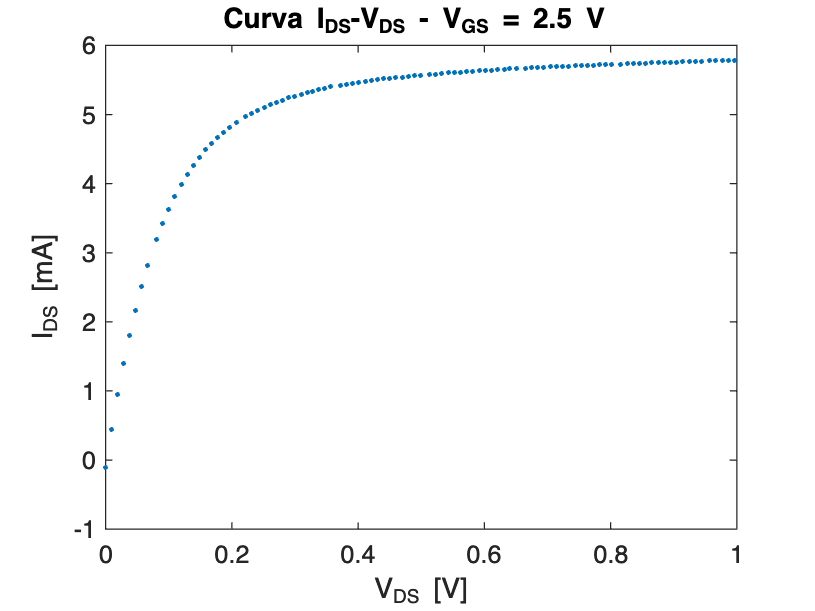

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 6 2');
Vd=datamat(:,1);
Id=datamat(:,2);
Vout=Id*R;
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_V/R)^2+(Vout/R^2*dR).^2); %digitalizzazione

plot(Vd, Id,'.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

$I_{DS}$ **per **$V_{DS}$ **regime lineare**

datamat=readmatrix('Data LAB es 6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:12);
Vd_fit=Vd(1:12);
Vout=Id_fit/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id_fit), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione

errorbar(Vd_fit, Id_fit*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId);
coefficiente=p(1)

coefficiente = 0.0474

dcoefficiente=dp(1)

dcoefficiente = 8.7147e-04

intercetta=p(2)

intercetta = -1.7869e-05

dintercetta=dp(2)

dintercetta = 2.6708e-05

chiqn

chiqn = 1.4305

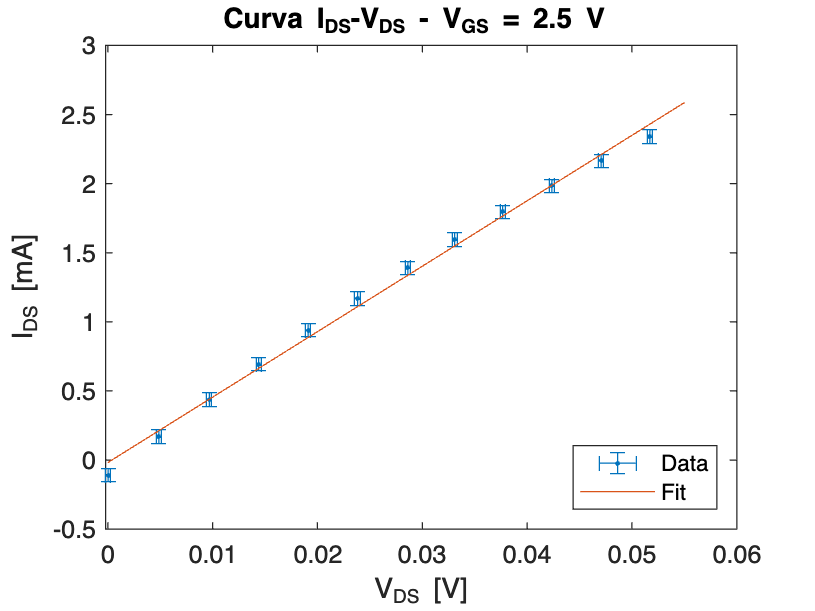

xx=linspace(0, 0.055, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=1;
Vg(i)=2.5;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $47.4 \pm 0.08$ mA/V

- intercetta = $-17 \pm 26$ $\mu$A (compatibile con 0)

- 
$$\chi^2_{norm} = 1.43$$


## Es. 7 - Corrente di Drain VS Tensione di Drain per diversi Vgs

Abbiamo poi ripetuto la stessa misura variando $V_{GS}$. Abbiamo preso valori di $V_{GS}$ piccoli (fino a 4 V), perché volevamo mantenere la corrente sotto i 10 mA, o comunque sotto i 20 mA. Per correnti superiori a questa, infatti, l'OpAmp smette di funzionare perché la sua *Short-circuit output current* vale 25 mA.

Abbiamo quindi impostato il range di $V_{DS$ per rimanere a correnti basse, anche se per $V_{GS}$ = 3 e 4 V siamo arrivati a 20 mA. 

Valori scelti di $V_{GS}$: 2.2, 2.3, 2.4, 2.6, 3, 4 V

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.3 V**

Per prima cosa abbiamo fatto un fit lineare, scegliendo i punti per cui l'andamento lineare sembrasse maggiormente rispettato. Dato che $V_{GS}$ è appena sopra la soglia, i punti per cui $V_{DS}/2$ è trascurabile rispetto a $V_{GS}-V_T$ sono pochi, quindi non è facile identificare la regione lineare. 

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,3');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:10);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=5*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1) 

coefficiente = 0.0150

dcoefficiente=dp(1)

dcoefficiente = 2.7683e-04

intercetta=p(2)

intercetta = -1.0811e-05

dintercetta=dp(2)

dintercetta = 7.1799e-06

chiqn

chiqn = 4.0419

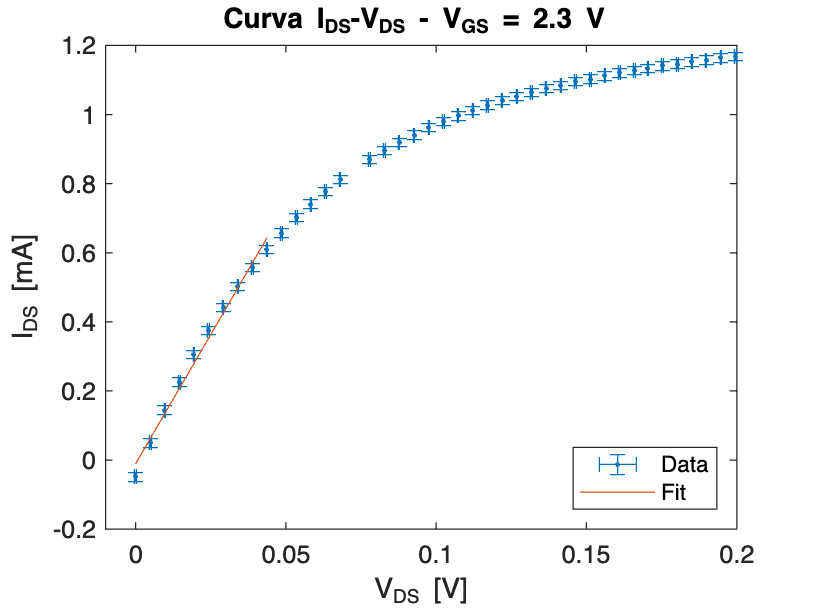

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

i=i+1;
Vg(i)=2.3;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $15. \pm 0.3$ mA/V

- intercetta = $-11 \pm 7$ $\mu$A 

- 
$$\chi^2_{norm} = 4$$


Però abbiamo selezionato solo 10 punti e l'andamento lineare non sembra comunque molto rispettato. Per questo motivo, per questa misura proviamo il modello completo, che vale per $V_{DS}<V_{GS}-V_T \simeq 0.1$ V: 


$$I_{DS} = K_n(V_{GS}-V_T) V_{DS} - \frac{K_n}{2} V_{DS}^2$$
 

Id_fit=Id(1:14);
Vd_fit=Vd(1:length(Id_fit));
max(Vd_fit);
Vout=Id/R;

dig_Vout=1*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

pin=[0, 0.25*(2.3-2.2), -0.25/2]';
modello = @(p,x)(p(1)+x*p(2)+x.^2*p(3));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vd_fit, Id_fit,modello,pin,'Weights', dId_fit.^(-2));
for j=1 : length(p)
err_parametri_fit(j)=sqrt(COVB(j,j));
end
chisq_norm=chi2n

chisq_norm = 2.8562

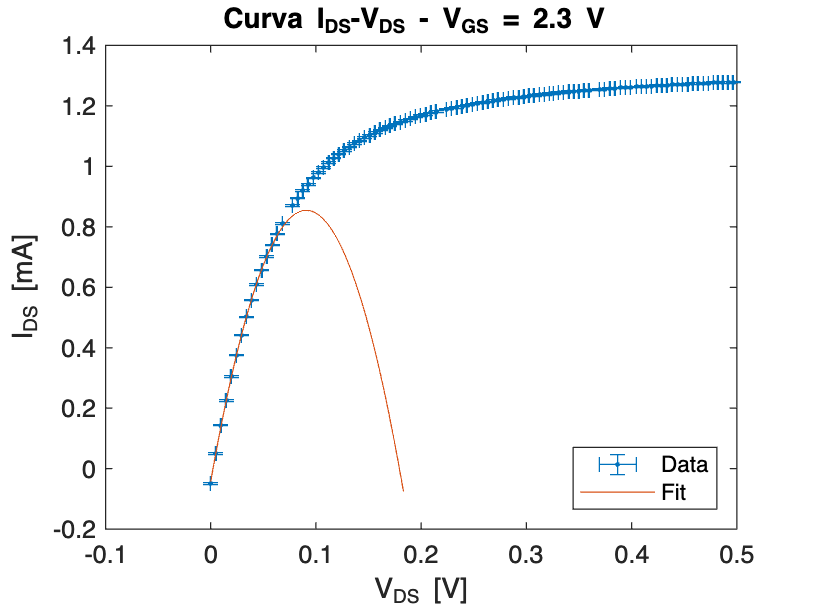

xx=linspace(0,max(Vd_fit)+0.12, 1000);
yy=p(1)+xx*p(2)+xx.^2*p(3);
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

Abbiamo fatto il fit per $V_{DS}$ fino a 0.06 V.

Risultati del fit, di modello p1+x*p2+x.^2*p3 :

- p1 = $-43 \pm 3$ $\mu$A (valore atteso: 0)

- p2 =  $19.8 \pm 0.2$ mA/V (valore atteso = $K_n (V_{GS}-V_T) \simeq 21$ mA/V) 

- p3 = $-0.109 \pm 0.003$ mA/V$^2$ (valore atteso $-K_n/2 \simeq -0.125$ mA/V$^2$) 

- 
$$\chi^2_{norm} = 2.86$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.4 V**

Anche qui $V_{GS}$ è troppo basso per poter identificare bene la regione lineare. Anche qui abbiamo usato i primi 10 punti per il fit lineare. 

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:10);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=5*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)  

coefficiente = 0.0294

dcoefficiente=dp(1)

dcoefficiente = 2.8000e-04

intercetta=p(2)

intercetta = -2.3708e-05

dintercetta=dp(2)

dintercetta = 7.1993e-06

chiqn

chiqn = 8.1194

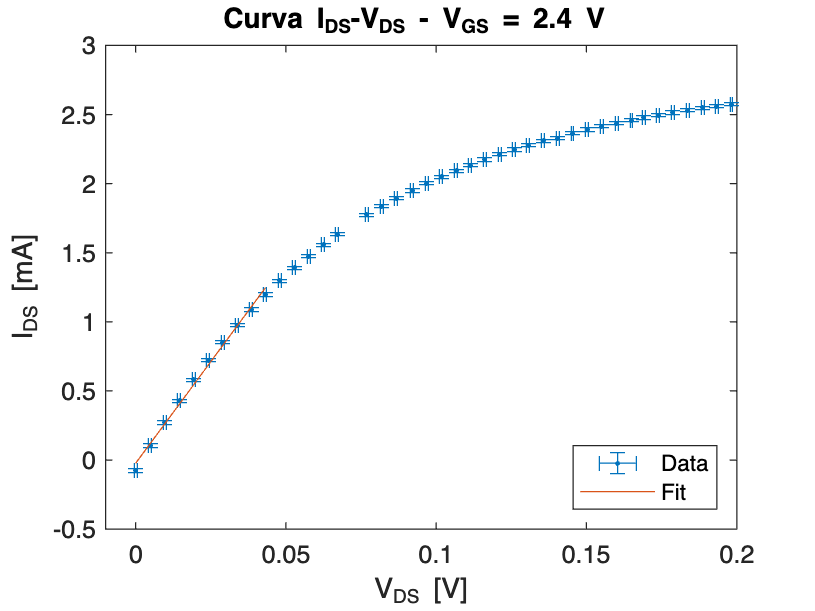

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

i=i+1;
Vg(i)=2.4;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente =  $29.4 \pm 0.3$ mA/V

- intercetta = $-23 \pm 7$$\mu$A 

- 
$$\chi^2_{norm} = 8.1$$


Su questa proviamo anche modello completo (parabola), che vale per $V_{DS}<V_{GS}-V_T \simeq 0.2$ V: 


$$I_{DS} = K_n(V_{GS}-V_T) V_{DS} - \frac{K_n}{2} V_{DS}^2$$
 

Id_fit=Id(1:25);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=1*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

pin=[0, 0.25*(2.4-2.2), -0.25/2]';
modello = @(p,x)(p(1)+x*p(2)+x.^2*p(3));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vd_fit, Id_fit,modello,pin,'Weights', dId_fit.^(-2));
for j=1 : length(p)
err_parametri_fit(j)=sqrt(COVB(j,j));
end

chisq_norm=chi2n

chisq_norm = 84.1834

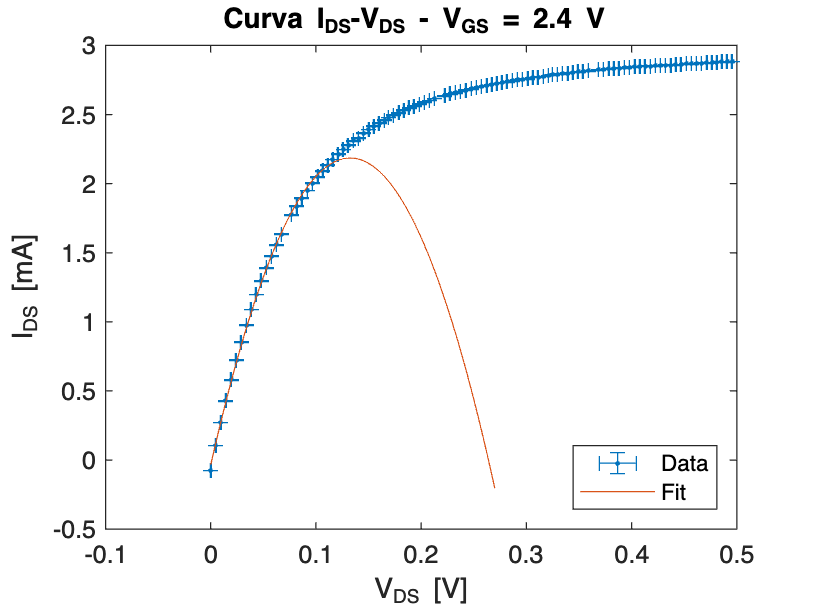

xx=linspace(0,0.27, 1000);
yy=p(1)+xx*p(2)+xx.^2*p(3);
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

Abbiamo fatto il fit per $V_{DS}$ fino a 0.12 V.

Risultati del fit, di modello p1+x*p2+x^2*p3 :  

- p1 = $-35 \pm 10$ $\mu$A (valore atteso: 0)

- p2 =  $33.5 \pm 0.5 $ mA/V (valore atteso = $K_n (V_{GS}-V_T) \simeq 50$ mA/V) 

- p3 = $-0.127 \pm 0.004$ mA/V$^2$ (valore atteso $-K_n/2 \simeq -0.125$ mA/V$^2$) 

- 
$$\chi^2_{norm} = 84$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.6 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.6 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.0675

dcoefficiente=dp(1)

dcoefficiente = 6.2578e-04

intercetta=p(2)

intercetta = 4.6127e-05

dintercetta=dp(2)

dintercetta = 2.4019e-05

chiqn

chiqn = 6.2456

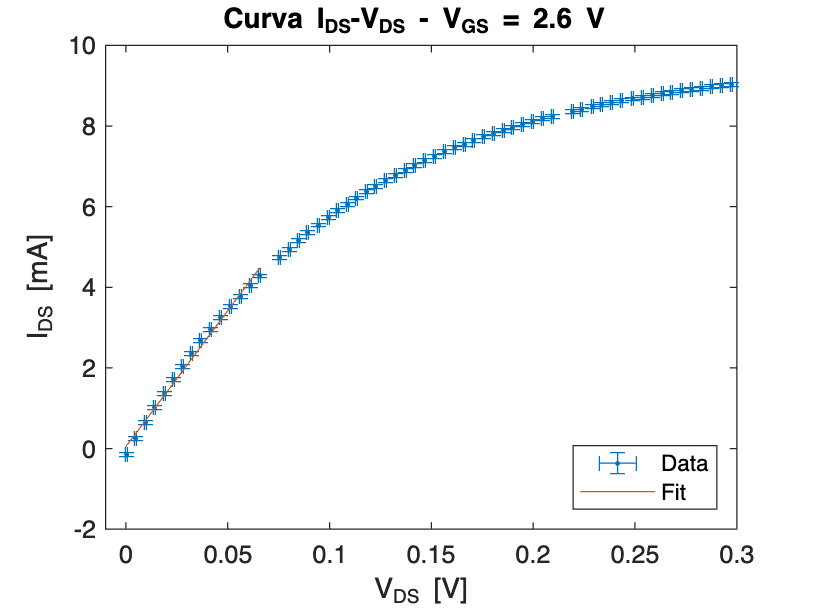

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);

xlim([-0.01, 0.3])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

i=i+1;
Vg(i)=2.6;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $67.5 \pm 0.6$ mA/V

- intercetta = $46 \pm 24$ $\mu$A 

- 
$$\chi^2_{norm} = 6.2$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 3 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:78);
Vd_fit=Vd(1:78);
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:78);
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.1765

dcoefficiente=dp(1)

dcoefficiente = 1.7383e-04

intercetta=p(2)

intercetta = 1.9845e-04

dintercetta=dp(2)

dintercetta = 1.0765e-05

chiqn

chiqn = 33.9379

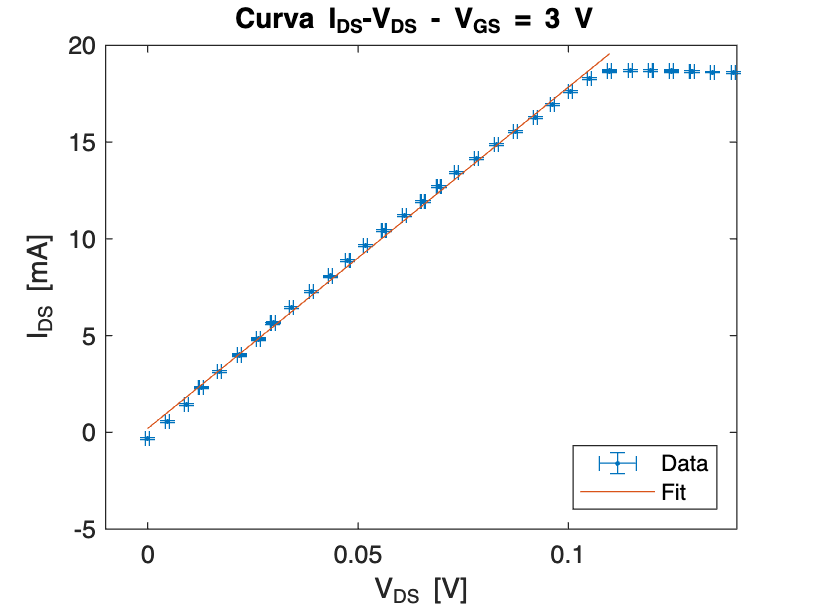

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
xlim([-0.01, 0.14])
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

i=i+1;
Vg(i)=3;
coeff(i)=p(1);
dcoeff(i)=dp(1);

Risultati del fit lineare: 

- coefficiente = $177.5 \pm 0.2$ mA/V

- intercetta = $0.16 \pm 0.01$ mA 

- 
$$\chi^2_{norm} = 28.7$$


In questo caso è stata raggiunta la corrente di 20 mA, la massima corrente con cui lavora il nostro OpAmp, quindi non abbiamo considerato le misure per valori di $V_{DS}$ superiori a 0.11 V. 

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 4 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:33);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.3773

dcoefficiente=dp(1)

dcoefficiente = 5.5277e-04

intercetta=p(2)

intercetta = -5.8803e-04

dintercetta=dp(2)

dintercetta = 1.6676e-05

chiqn

chiqn = 5.9353

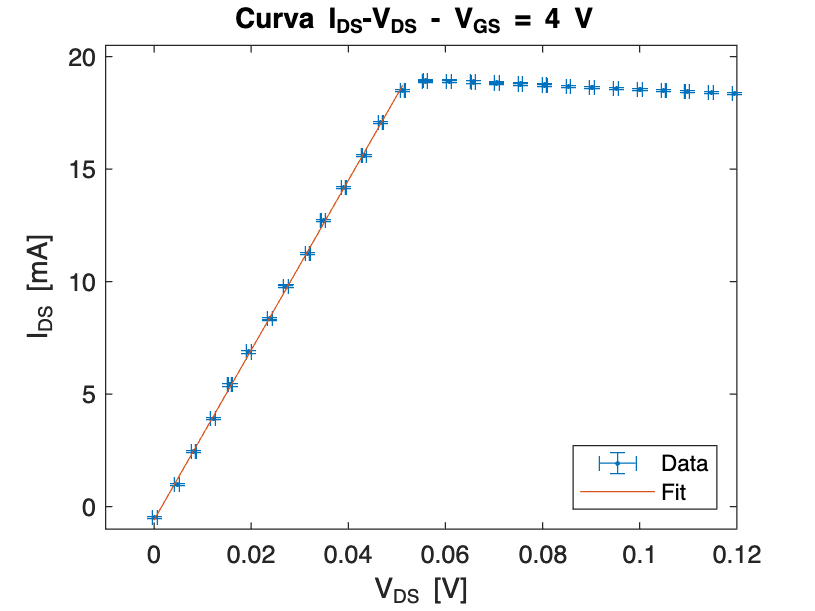

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
ylim([-1,20.5])

xlim([-0.01, 0.12])
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

i=i+1;
Vg(i)=4;
coeff(i)=p(1);
dcoeff(i)=dp(1);

Risultati del fit lineare: 

- coefficiente = $377.3 \pm 0.6$ mA/V

- intercetta = $-0.59 \pm 0.02$ mA 

- 
$$\chi^2_{norm} = 5.9$$


Anche in questo caso è stata raggiunta la corrente di 20 mA, la massima corrente con cui lavora il nostro OpAmp, quindi non abbiamo considerato le misure per valori di $V_{DS}$ superiori a 0.05 V. 

**Studio del coefficiente **$I_{DS}/V_{DS}$ **al variare di **$V_{GS}$

Il valore atteso per il coefficiente $I_{DS}/V_{DS}$, se $V_{DS} \ll V_{GS}-V_T$, è dato da :

$K_n (V_{GS}-V_T)$, con $K_n = 0.25$ A/V$^2$. 

Fit lineare di $I_{DS}/V_{DS}$ VS $V_{GS}$:

errorbar(Vg, coeff, dcoeff, dcoeff, '.')
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vg, coeff, dcoeff);
coefficiente=p(1)

coefficiente = 0.2249

dcoefficiente=dp(1)

dcoefficiente = 2.9488e-04

intercetta=p(2)

intercetta = -0.5035

dintercetta=dp(2)

dintercetta = 8.2601e-04

Vt=-intercetta/coefficiente

Vt = 2.2393

dVt=sqrt((dintercetta/coefficiente)^2+(intercetta/coefficiente^2*dcoefficiente)^2)

dVt = 0.0047

chiqn

chiqn = 839.1513

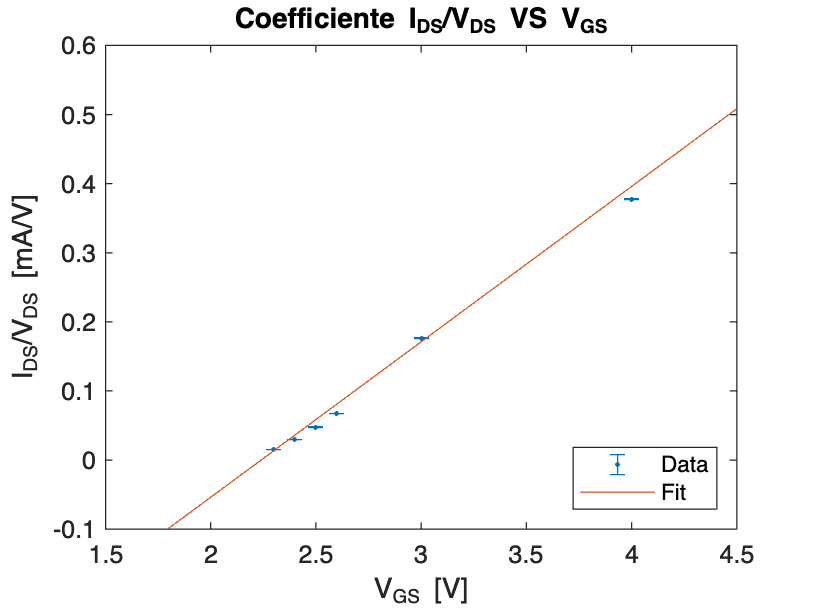

xx=linspace(min(Vg)-0.5, max(Vg)+0.5, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy)
hold off
legend('Data', 'Fit', 'Location','southeast')
title('Coefficiente I_{DS}/V_{DS} VS V_{GS}')
xlabel('V_{GS} [V]')
ylabel('I_{DS}/V_{DS} [mA/V]')

Risultati del fit lineare: 

- $K_n$ = $0.2252 \pm 0.0003$ A/V$^2$

- intercetta = $-K_n V_T$= $-0.5043 \pm 0.0008$ A/V 

- $V_T = 2.239 \pm 0.005$ V

- 
$$\chi^2_{norm} = 913$$


Si ha un $K_n$ di 0.2252 A/V$^2$, non compatibile con quello atteso di circa 0.25, ma dello stesso ordine di grandezza, e lo stesso si può dire per la misura indiretta di $V_T$, che viene leggermente più alta di quella da noi individuata, ovvero 2.1 V.

Il chi quadro normalizzato viene grande perché gli errori su $I_{DS}/V_{DS}$ sono sottostimati.

## Es. 8: Corrente di Drain VS Tensione di Gain

Abbiamo usato il circuito dei punti precedenti, sempre con Rtrans = 100 Ohm.

Relazione attesa:

 $I_{DS} = \frac{K}{2} (V_{GS}-V_T)^2$ dove $K=K_n(1+\lambda V_{DS})$

Modello usato per i fit: $I_{DS} = p_1 + p_2 V_{GS}+ p_3 V_{GS}^2$ con:

- 
$$p_1 =V_{T}^2 \cdot K/2$$


- 
$$p_2=-2 \cdot V_T\cdot K/2$$


- 
$$p_3 = K/2$$


Si ha quindi: 

- 
$$K = 2\cdot p_3$$


- 
$$V_T = - p_2/K$$


Inizialmente abbiamo preso una misura della curva $I_{DS}$ VS $V_{DS}$ scegliendo $V_{DS}$ in modo da essere in regime lineare. Ci siamo accorti dopo aver preso la misura che non era la richiesta dell'esercizio e abbiamo quindi alzato $V_{DS}$ in modo da misurare in regime di saturazione. 

**Prima misura (sbagliata, in regime lineare) - **$V_{DS}$ **= 0.08 V **

Abbiamo scelto $V_{DS}$= 0.08 V in modo da essere in regime lineare, ma senza prenderlo troppo alto per avere I sotto 10 mA a $V_{GS}$ sopra la soglia. 

Abbiamo inizialmente fatto variare $V_{GS}$ a partire da 1,5 V e la corrente è costantemente 0 fino a $V_{GS}$= 2 V. 

Per questo motivo, abbiamo scelto l'intervallo per $V_{GS}$ sul vi a partire da 2 V e fino al valore per cui $I_{DS}$  rimane sotto i 10 mA.

Per questa prima misura, $V_{GS}$ varia  tra 2 e 2.9 V. 

R=100;%ohm
dR=1;
Vds=0.08;
datamat=readmatrix('Data LAB es 8');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

Abbiamo fatto un fit parabolico per vedere come cambiano i parametri rispetto alla zona di saturazione, analizzata dopo. 


%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 32.4401

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.0826


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 0.5126

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0501

chi2=chi2n

chi2 = 9.8157

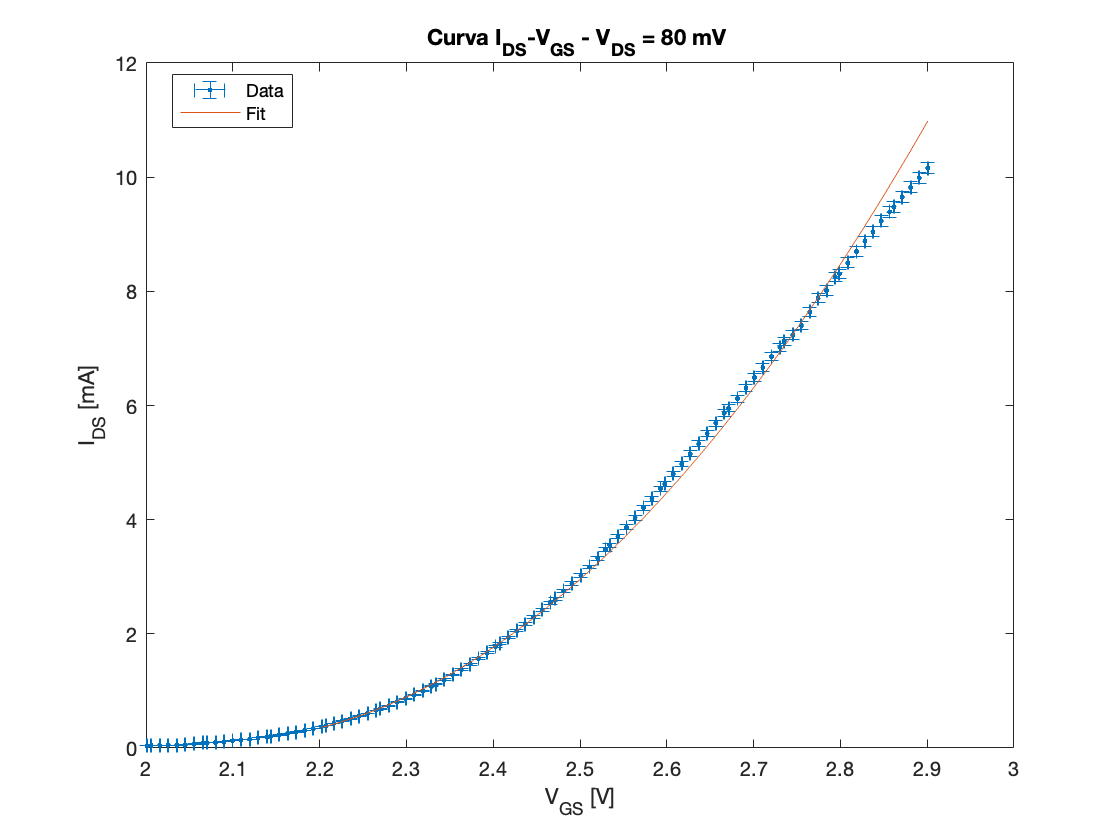



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 80 mV ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=32.4 \pm 0.5$ mA/V$^2$

- $V_T = 2.08 \pm 0.05$ V

- 
$$\chi^2_{norm} = 9.8$$


**Seconda misura (in regime di saturazione) - **$V_{DS}$ **= 1 V **

$V_{GS}$ varia  tra 2 e 2.6 V 

Abbiamo fatto anche qui un fit parabolico come sopra.


R=100;%ohm
dR=1;
Vds=1;
datamat=readmatrix('Data LAB es 8 vd 1');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 99.3828

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.1749


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 1.8552

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0593

chi2=chi2n

chi2 = 12.0473

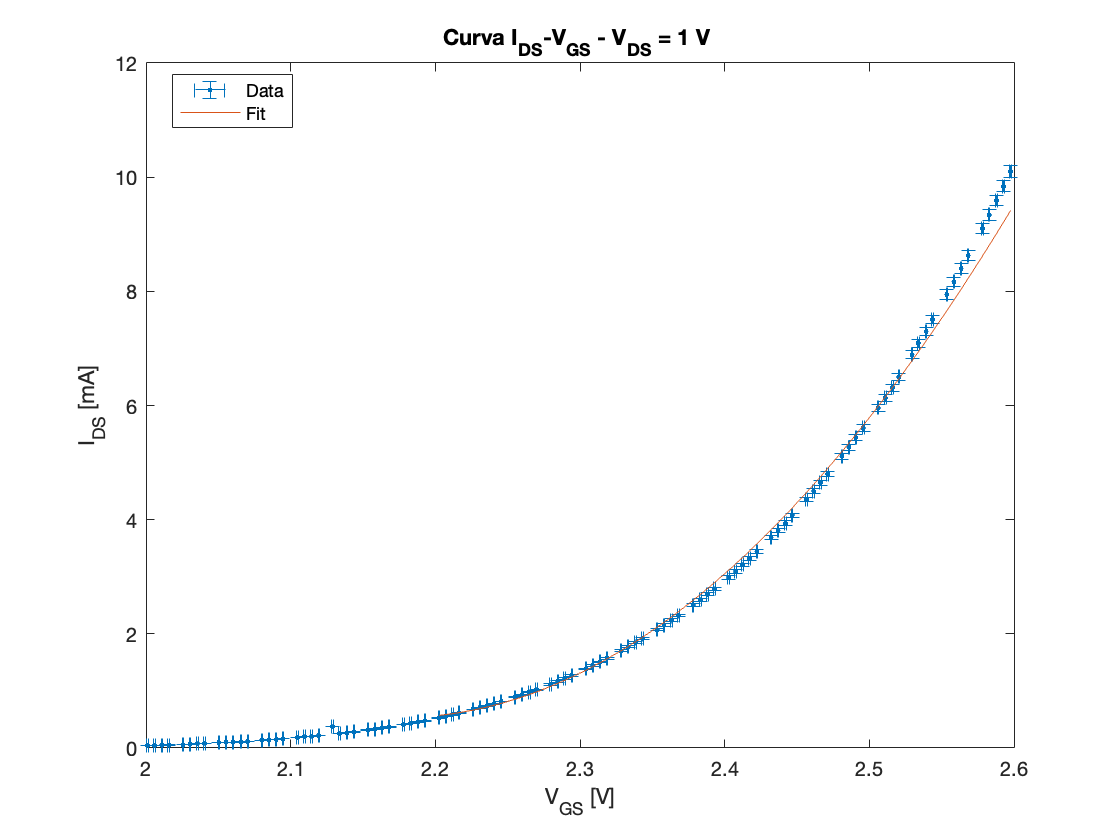



l=1;
kn(l)=k_fit; %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=Vt_fit;
dkn(l)=dk_fit;
l=l+1;



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 1 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=92 \pm 2$ mA/V$^2$

- $V_T = 2.16 \pm 0.06$ V

- 
$$\chi^2_{norm} = 19$$


## Es. 9: Corrente di Drain VS Tensione di Gain per diversi Vds

Abbiamo ripetuto per diversi valori di $V_{DS}$ le misure descritte al punto precedente. 

Abbiamo preso due misure in regime lineare ($V_{DS}$ = 0.1 V e 0.09 V) e due misure in regime di saturazione ($V_{DS}$ =3.3 V e 4V).

**Regime lineare - **$V_{DS}$ **= 0.1 V**

 $V_{GS}$ varia tra 2 e 2.6 V.

R=100;%ohm
dR=1;
Vds=0.1;
datamat=readmatrix('Data LAB es 9');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 47.9445

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.1351


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 0.3110

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0205

chi2=chi2n

chi2 = 0.7991

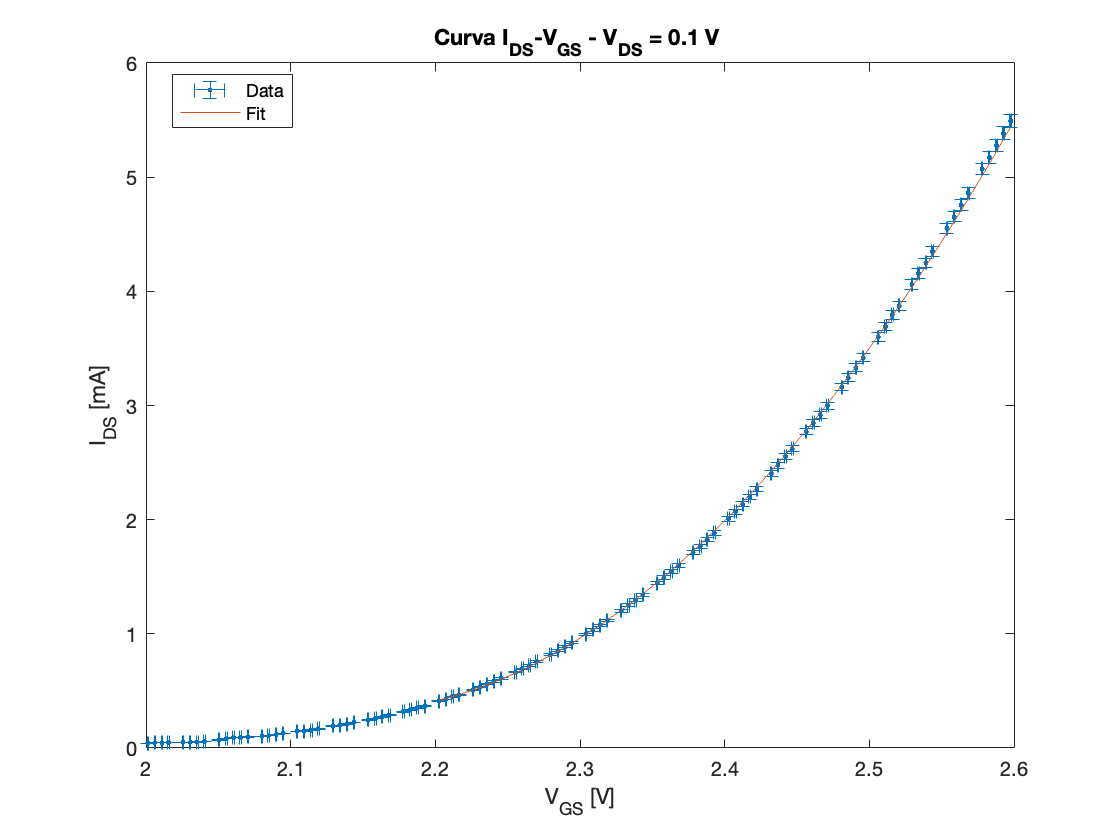




%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 0.1 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=47.9 \pm 0.3$ mA/V$^2$

- $V_T = 2.14 \pm 0.02$ V

- 
$$\chi^2_{norm} = 0.8$$


**Regime lineare - **$V_{DS}$ **= 0.09 V**

 $V_{GS}$ varia  tra 2 e 2.7 V.

R=100;%ohm
dR=1;
Vds=0.09;
datamat=readmatrix('Data LAB es 9 2');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 43.7820

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.1298


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 0.1903

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0138

chi2=chi2n

chi2 = 0.5075

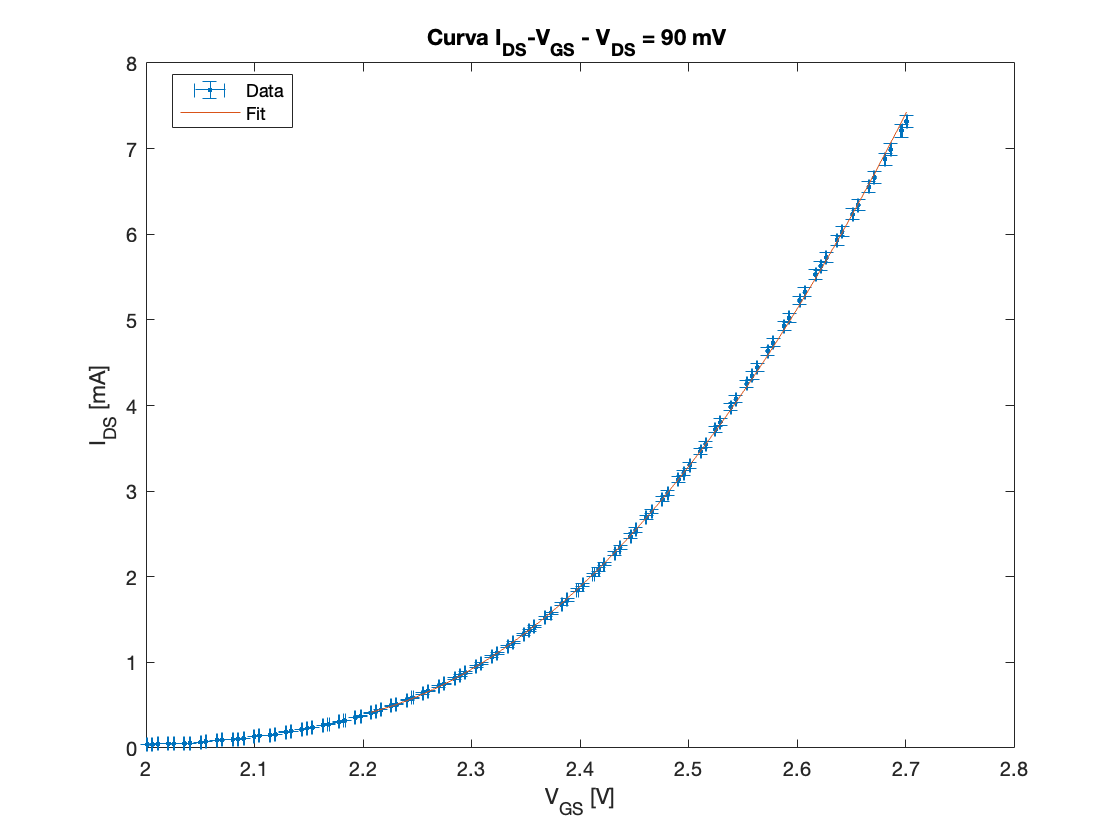



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 90 mV ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=43.8 \pm 0.2$ mA/V$^2$

- $V_T = 2.13 \pm 0.01$ V

- 
$$\chi^2_{norm} = 0.5$$


**Regime di saturazione - **$V_{DS}$ **= 3.3 V**

 $V_{GS}$ varia  tra 2 e 2.5 V.

R=100;%ohm
dR=1;
Vds=3.3;
datamat=readmatrix('Data LAB es 9 vd 3,3');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end


%fit
kexp=140;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 93.4916

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.1606


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 1.5283

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0516

chi2=chi2n

chi2 = 3.9666

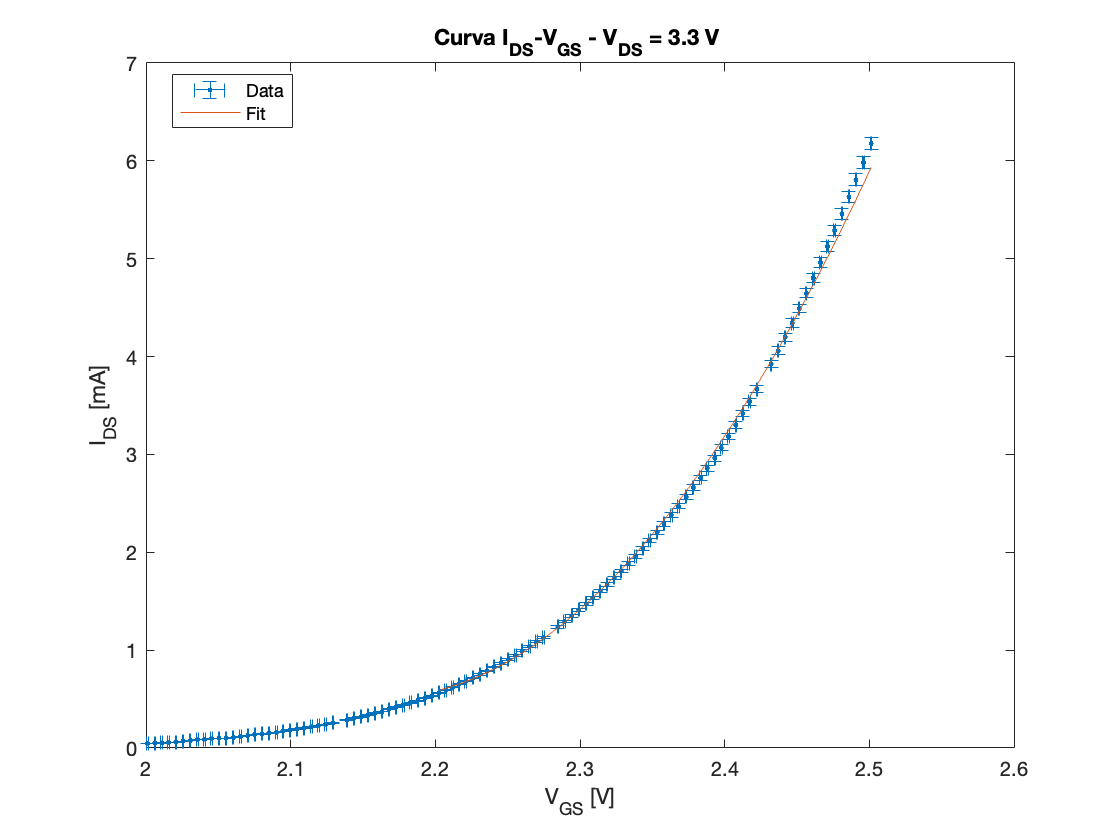


kn(l)=k_fit; %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=Vt_fit;
dkn(l)=dk_fit;
l=l+1;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 3.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=93 \pm 2$ mA/V$^2$

- $V_T = 2.16 \pm 0.05$ V

- 
$$\chi^2_{norm} = 4$$


**Regime di saturazione - **$V_{DS}$ **= 4 V**

 $V_{GS}$ varia  tra 2 e 2.5 V.

R=100;%ohm
dR=1;
Vds=4;
datamat=readmatrix('Data LAB es 9 vd 4');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit = 94.8084

Vt_fit=-p(2)/2/p(3)

Vt_fit = 2.1610


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit = 1.8088

dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit = 0.0602

chi2=chi2n

chi2 = 5.3617

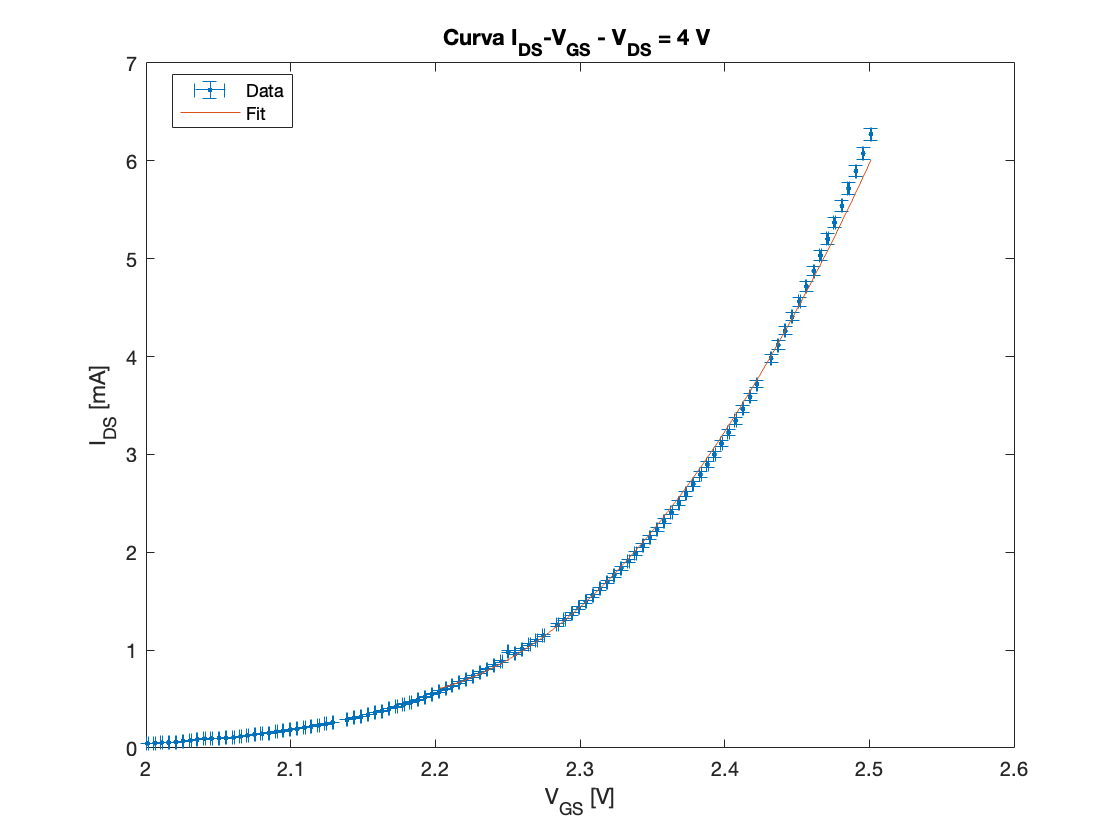


kn(l)=k_fit; %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=Vt_fit;
dkn(l)=dk_fit;



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit,Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=94 \pm 2$ mA/V$^2$

- $V_T = 2.16 \pm 0.06$ V

- 
$$\chi^2_{norm} = 5.4$$


**Grafico unico:**

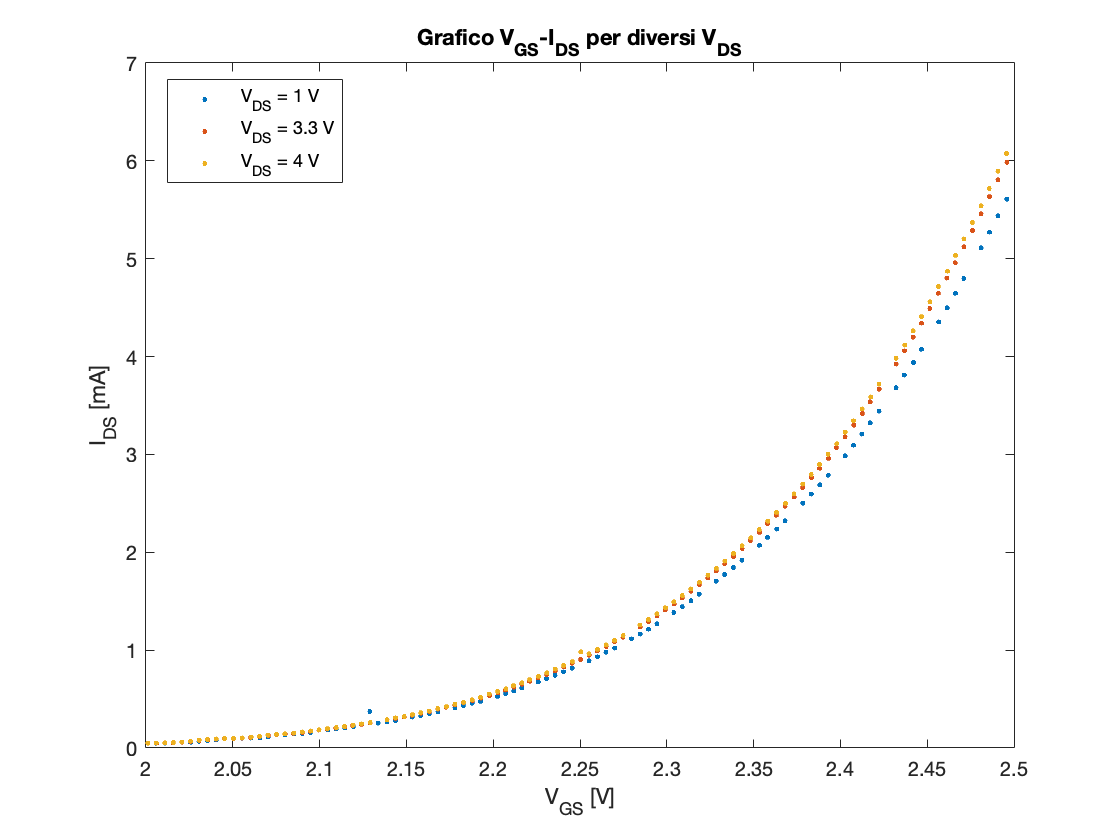

datamat=readmatrix('Data LAB es 8 vd 1');
Vgs1=datamat(:,1);
Ids1=datamat(:,2);
datamat=readmatrix('Data LAB es 9 vd 3,3');
Vgs2=datamat(:,1);
Ids2=datamat(:,2);
datamat=readmatrix('Data LAB es 9 vd 4');
Vgs3=datamat(:,1);
Ids3=datamat(:,2);

plot(Vgs1, Ids1, '.')
hold on
plot(Vgs2, Ids2, '.')
plot(Vgs3, Ids3, '.')
hold off
title('Grafico V_{GS}-I_{DS} per diversi V_{DS}')
xlim([2, 2.5])
xlabel('V_{GS} [V]')
ylabel('I_{DS} [mA]')
legend('V_{DS} = 1 V', 'V_{DS} = 3.3 V', 'V_{DS} = 4 V', 'Location', 'best')

## Es. 10 - Misura della transconduttanza

Dai risultati misuriamo ora $p_1$ per i dati nella regione lineare. 

knm=mean(kn)

knm = 95.8943

dknm=knm*sqrt(((dkn(1)/kn(1))^2)+((dkn(2)/kn(2))^2)+((dkn(3)/kn(3))^2))

dknm = 3.0014

Vtm=mean(Vt)

Vtm = 2.1655

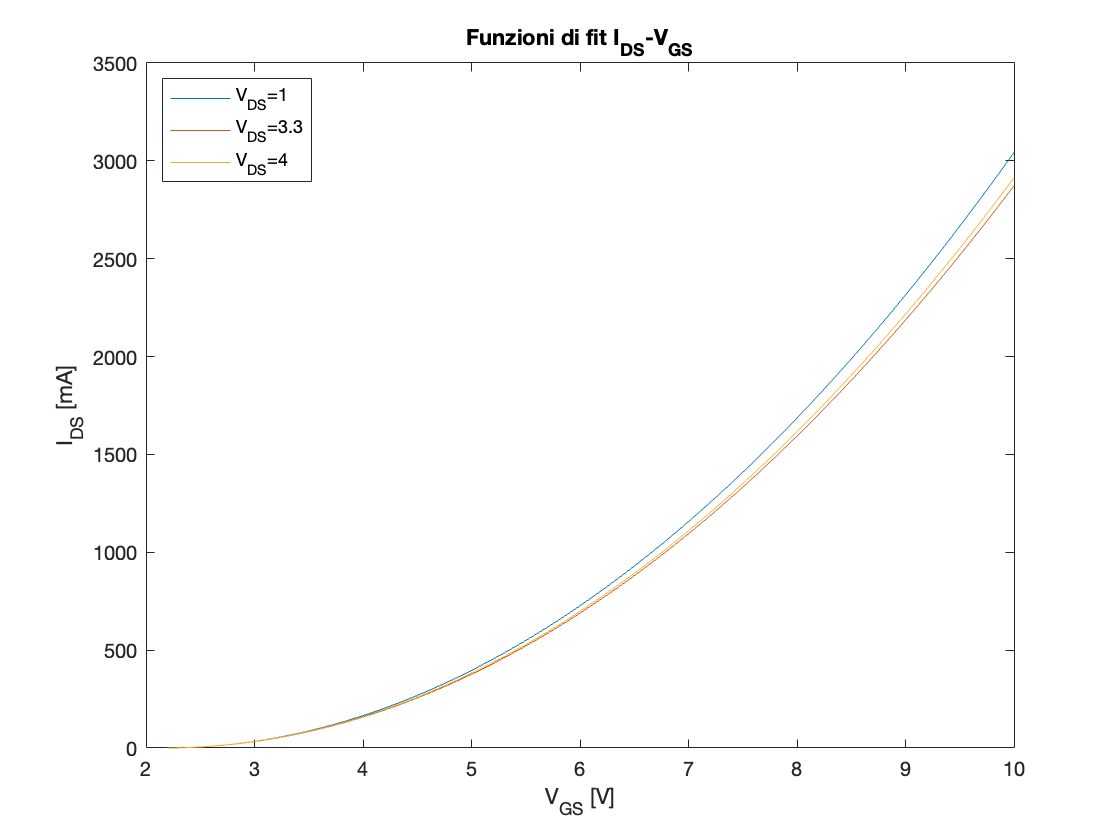

%grafico ora i risultati dei fit per i vari Vdt
xx=linspace(2.2, 10, 1000);
yy=modello([kn(1)/2*Vt(1)^2, -2*kn(1)/2*Vt(1), kn(1)/2], xx);
tt=modello([kn(2)/2*Vt(2)^2, -2*kn(2)/2*Vt(2), kn(2)/2], xx);
zz=modello([kn(3)/2*Vt(3)^2, -2*kn(3)/2*Vt(3), kn(3)/2], xx);

plot(xx, yy);
hold on
plot(xx, tt);
plot(xx, zz);
hold off
title('Funzioni di fit I_{DS}-V_{GS}')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('V_{DS}=1', 'V_{DS}=3.3', 'V_{DS}=4', 'Location','northwest')

Transconduttanza: $g_m=K(V_{GS}-V_T)=2\sqrt{I_{DS}\frac{K_n(1+\lambda V_{DS})}{2} }$

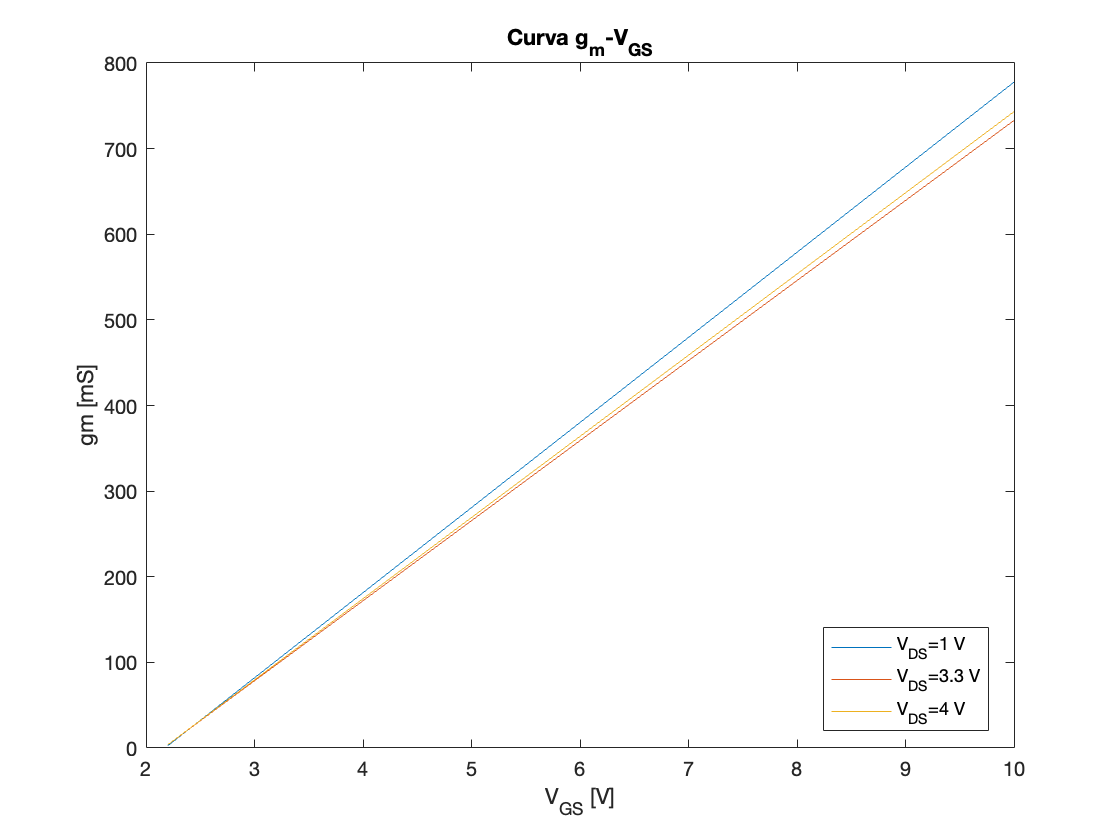

gm1=kn(1)*(xx-Vt(1));
gm2=kn(2)*(xx-Vt(2));
gm3=kn(3)*(xx-Vt(3));

plot(xx, gm1)
hold on
plot(xx, gm2);
plot(xx, gm3);
hold off
title('Curva g_m-V_{GS}')
ylabel('gm [mS]')
xlabel('V_{GS} [V]')
legend('V_{DS}=1 V', 'V_{DS}=3.3 V', 'V_{DS}=4 V', 'Location','best')


%stima di lambda e di kn con 2 misure (relative a  3.3 e 4 V)
kns=(kn(3)-(4/3.3)*kn(2))/(1-4/3.3)

kns = 87.2843

dkns=sqrt((dkn(3)/kn(3))^2+(4*dkn(2)/(kn(2)*3.3))^2)

dkns = 0.0275

lambda=(kn(2)/kns-1)/3.3

lambda = 0.0216

dlambda=lambda*sqrt((dkn(2)/kn(2))^2+(dkns/kns)^2)

dlambda = 3.5234e-04



Vds= 10; %V
Ids= 200;%mA
gm_manuale=2*sqrt(0.5*kns*(1+Vds*lambda)*Ids)

gm_manuale = 206.0044

dgm=gm_manuale*dlambda/lambda %propago solo dlambda poichè gli altri sono trascurabili

dgm = 3.3681


%stima di lambda e di kn con 2 misure (relative a  1 e 3.3 V)
kns2=(kn(1)-(1/3.3)*kn(2))/(1-1/3.3)

kns2 = 101.9442

dkns2=sqrt((dkn(1)/kn(1))^2+(4*dkn(2)/(kn(2)*3.3))^2)

dkns2 = 0.0272

lambda2=(kn(2)/kns2-1)/3.3

lambda2 = -0.0251

dlambda2=lambda2*sqrt((dkn(2)/kn(2))^2+(dkns2/kns2)^2)

dlambda2 = -4.1077e-04



Vds= 10; %V
Ids= 200;%mA
gm_manuale2=2*sqrt(0.5*kns2*(1+Vds*lambda2)*Ids)

gm_manuale2 = 174.7345

dgm2=gm_manuale2*dlambda2/lambda2 %propago solo dlambda poichè gli altri sono trascurabili

dgm2 = 2.8567

Sul manuale valore tipico è $g_m=$ 320 mS, misurato per $V_{DS} = 10$ V, $I_{DS}$ = 200 mA.

Otteniamo $g_m =206 \pm 3$ mS, che non è compatibile con il valore del datasheet. Possiamo ricondurlo alle poche misure acquisite in regime di saturazione, con successiva poca accuratezza nella stima di $k_n $e di $\lambda$.

## Es. 11: Corrente di Drain VS Tensione di Gain con generatore

Abbiamo preso delle misure impostando $V_{DS}$ = 2.5 V dal generatore, in modo da poter arrivare a usare una corrente di circa 30 mA, in quanto non abbiamo più il vincolo di 10mA della scheda National. 

Si vede però che usando l'OpAmp uA741C si ha un massimo di $I_{DS}$ a circa 20 mA, dovuto alla corrente massima con cui questo può lavorare (indicata come $I_{OS}$ nel datasheet), ovvero 25 mA.

Abbiamo quindi usato l'OpAmp OP37, che permette di arrivare a correnti maggiori. 

Abbiamo impostato $V_{DS}$ a 2.5 V con il generatore e usato Rtrans = 150 Ohm (1% toll).

**Prima misura: **$V_{DS}$ **= 2.5 V**

R=150;%ohm
dR=1.5;
Vds=2.5;
datamat=readmatrix('Data LAB es 11 OP37');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
for i= 1 : length(Vgs) %gli ultimi punti tornano a calare perchè I>35mA
    if Ids(i)>31
        aa(i)=0;
    end
end
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : (length(Ids))
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp, 2,0.1]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2)*(1+p(3)*Vds));
%modello=@(p,x)(kns*(1+p(1)*Vds)+p(2)*x+p(3)*x.^2);


%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));

parametri_fit=p;
kn_fit=p(1)

kn_fit = 66.1452

Vt_fit=p(2)

Vt_fit = 2.0958

lambda_fit=p(3)

lambda_fit = 0.1512


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end

dk_fit=err_parametri(1)

dk_fit = 2.8148e-04

dVt_fit=err_parametri(2);
dlambda_fit=err_parametri(3)

dlambda_fit = 0.0338

chi2=chi2n

chi2 = 165.7760

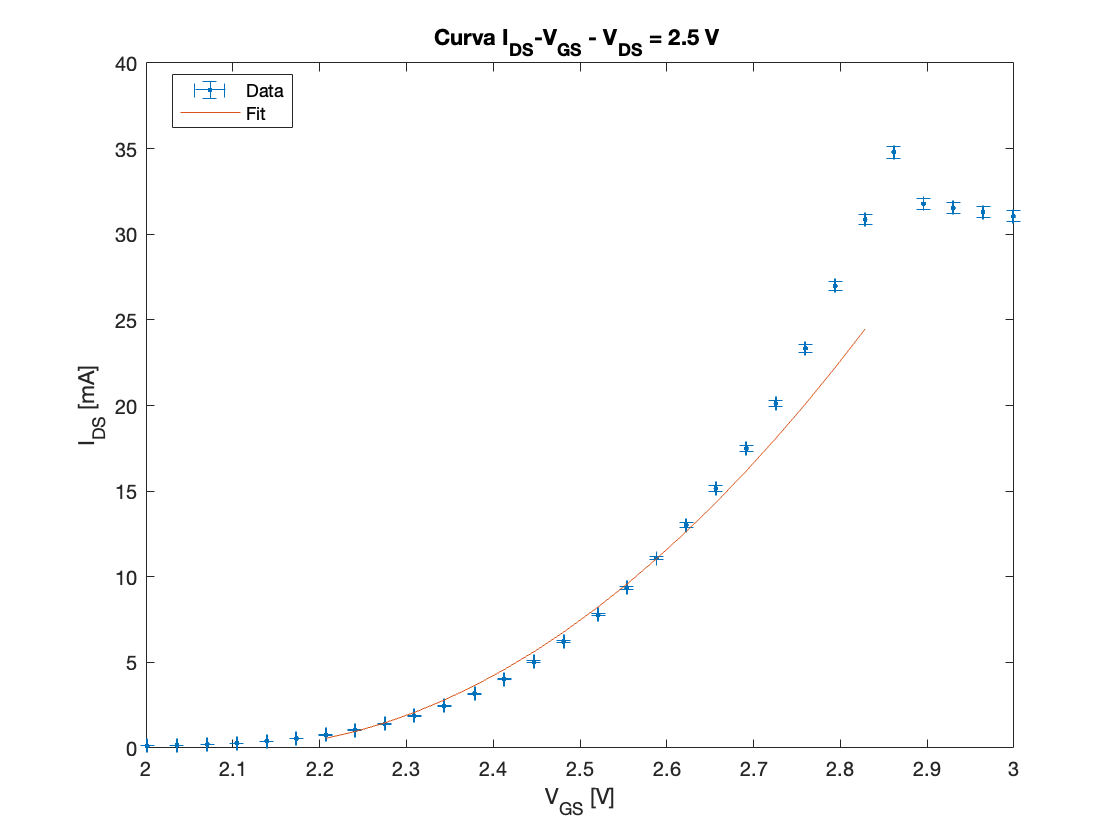


kn37(1)=kn_fit;
dkn37(1)=dk_fit;
lambda37(1)=lambda_fit;
dlambda37(1)=dlambda_fit;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Ripetiamo la misura con gli stessi valori, ma con un altro componente, sempre OP37.

R=150;%ohm
dR=1.5;
Vds=2.5;
datamat=readmatrix('Data LAB es 11 OP37 2');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa)-4);
Vgs_fit = ones(1, sum(aa)-4);
dIds_fit = ones(1, sum(aa)-4);
for i = 1 : (length(Ids)-4)  %gli ultimi punti tornano a calare perchè I>35mA
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp, 2,0.1]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2)*(1+p(3)*Vds));
%modello=@(p,x)(kns*(1+p(1)*Vds)+p(2)*x+p(3)*x.^2);


%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));

parametri_fit=p;
kn_fit=p(1)

kn_fit = 67.1641

Vt_fit=p(2)

Vt_fit = 2.0970

lambda_fit=p(3)

lambda_fit = 0.1597


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end

dk_fit=err_parametri(1)

dk_fit = 2.8155e-04

dVt_fit=err_parametri(2);
dlambda_fit=err_parametri(3)

dlambda_fit = 0.0338

chi2=chi2n

chi2 = 175.6064

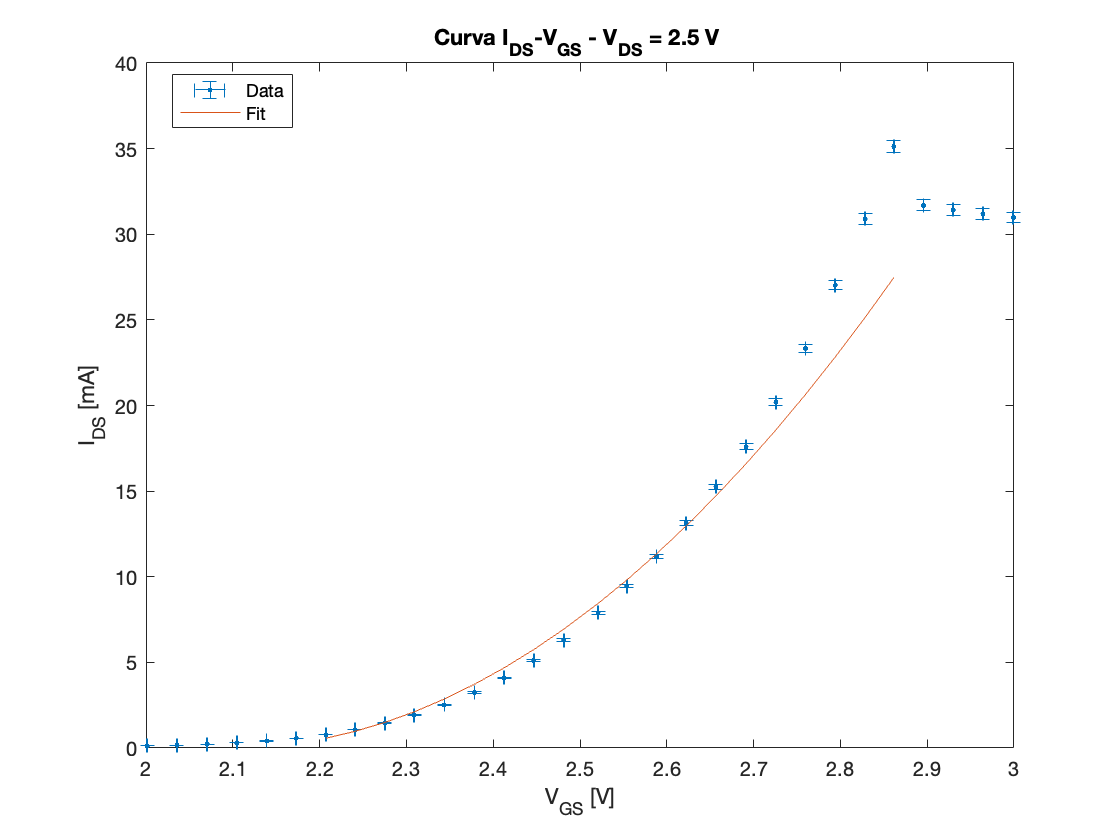


kn37(2)=kn_fit;
dkn37(2)=dk_fit;
lambda37(2)=lambda_fit;
dlambda37(2)=dlambda_fit;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Grazie al modello OP37 siamo riusciti a lavorare fino a correnti di 30 mA, il che dovrebbe permetterci di avere una misura migliore della transconduttanza.

## Es. 12 - Misura della transconduttanza pt.2

Ripetiamo la stima della transconduttanza utilizzando i nuovi dati acquisiti nell'intervallo di corrente maggiore.

Transconduttanza: $g_m=p_1(V_{GS}-V_T)=2\sqrt{I_{DS}\frac{K_n(1+\lambda V_{DS})}{2} }$

Vds=10;
Ids=200;
kns37=sum(kn37)/2

kns37 = 66.6547

dkn=sqrt((dkn37(1)^2)+(dkn37(2)^2))

dkn = 3.9812e-04

lambda=sum(lambda37)/2

lambda = 0.1555

dlambda=sqrt((dlambda37(1)^2)+(dlambda37(2)^2))

dlambda = 0.0478

gm_manuale=2*sqrt(0.5*kns37*(1+lambda*Vds)*Ids)

gm_manuale = 260.9779

dgm=gm_manuale*dlambda/lambda %propago solo l'errore di lambda, è molto maggiore degli altri

dgm = 80.2029

gm_manuale_tipico = 316.2278

lambda_exp = 0.1778

kn_exp = 90

kn_exp = 90

Misuriamo $g_m=244 \pm 75 \,\,\, mS$, contro il valore del datasheet di $g_m = 320 \,\,mS$.

Avendo acquisito solo due misure e con due OpAmp diversi, possiamo solo commentare il fatto che la misura è sensibilmente migliorata rispetto a quella fatta con correnti minori, nonostante non sia compatibile con il valore atteso.

## Es. 13: FET J105

Ripetiamo le misure con il fet J105, che a differenza del MOSFET utilizzato in precedenza ha una Vt negativa.

Dobbiamo modificare i .vi per l'utilizzo di questo: imporre una tensione negativa all'uscita quando finiscono le acquisizioni.

Andare in FET_vs_DRAIN.vi: alla fine nel 9 modifica il valore di CB22 (ao0) a 0: modificare quella costante da 0 al valore desiderato  (-10 V)

Poi nel primo frame (0) cambiare l'intervallo massimo da 5 a 10, così si può andare negativi 

Modificato e creato nuovo .vi: JFET_vs_DRAIN 

### **Curva Id-Vds**

Vogliamo rimanere sempre sotto 10 mA

Soglia è tra -7  (I sempre 0) e -6.5 V (fa retta)

**Misura 1:**

Vg= -6.5 e Vd tra 0 e 2.4 V (misura 13-6)

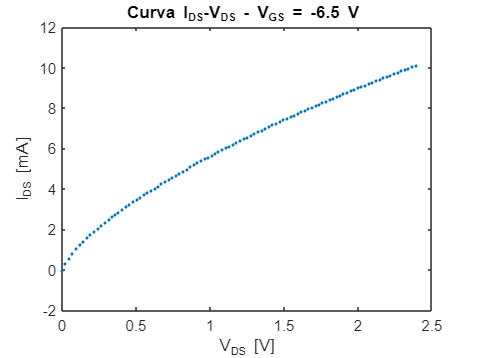

R=150;%ohm
dR=1.5;
datamat=readmatrix('Data LAB es 13-6');
Vd=datamat(:,1);
Id=datamat(:,2);
Vout=Id*R;
dig_V=20*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_V/R)^2+(Vout/R^2*dR).^2); %digitalizzazione propagato

plot(Vd, Id,'.')
title('Curva I_{DS}-V_{DS} - V_{GS} = -6.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

$I_{DS}$ **per **$V_{DS}$ **regime lineare**

datamat=readmatrix('Data LAB es 13-6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:10);
Vd_fit=Vd(1:10);
Vout=Id_fit/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id_fit), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId);
coefficiente=p(1)

coefficiente =    0.008656028722165


dcoefficiente=dp(1)

dcoefficiente =      1.469540750318928e-04


intercetta=p(2)

intercetta =      1.059661527215952e-04


dintercetta=dp(2)

dintercetta =      1.912908309050957e-05


chiqn

chiqn =    6.075527884477172


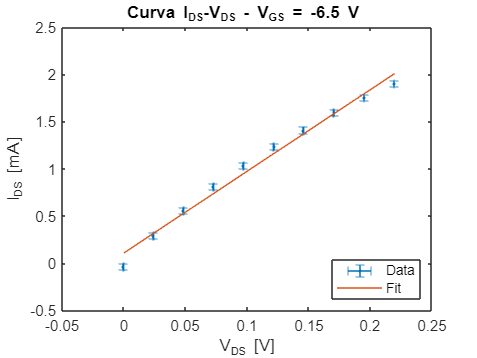

xx=linspace(min(Vd_fit), max(Vd_fit), 1000);
yy=p(1)*xx+p(2);

%grafici
errorbar(Vd_fit, Id_fit*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = -6.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

Risultati del fit lineare: 

- coefficiente = $8.6 \pm 0.1$ mA/V;

- intercetta = $106 \pm 19$ $\mu$A;

- $\chi^2_{norm} = 6.1$.

**Misura 2:**

 Vg = -6.4, Vd tra 0 e 1.5 V (misura 13-7)

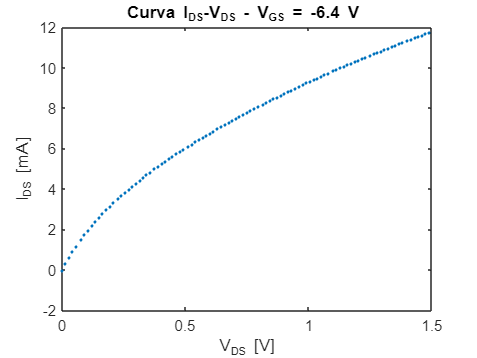

R=150;%ohm
dR=1.5;
datamat=readmatrix('Data LAB es 13-7');
Vd=datamat(:,1);
Id=datamat(:,2);
Vout=Id*R;
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_V/R)^2+(Vout/R^2*dR).^2); %digitalizzazione

plot(Vd, Id,'.')
title('Curva I_{DS}-V_{DS} - V_{GS} = -6.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

$I_{DS}$ **per **$V_{DS}$ **regime lineare**

datamat=readmatrix('Data LAB es 13-7');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:12);
Vd_fit=Vd(1:12);
Vout=Id_fit/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id_fit), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione

errorbar(Vd_fit, Id_fit*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = -6.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId);
coefficiente=p(1)

coefficiente =    0.016918025352908


dcoefficiente=dp(1)

dcoefficiente =      1.799840089146893e-04


intercetta=p(2)

intercetta =      9.808976943134675e-05


dintercetta=dp(2)

dintercetta =      1.763611792606519e-05


chiqn

chiqn =    6.749446824854957


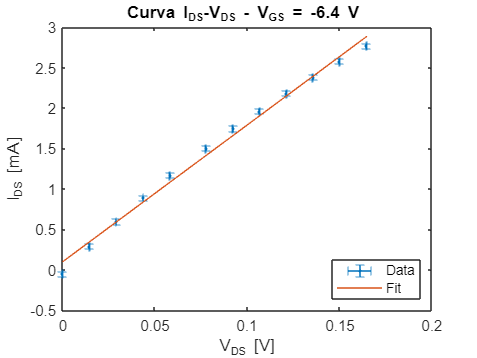

xx=linspace(min(Vd_fit), max(Vd_fit), 1000);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')

Risultati del fit lineare: 

- coefficiente = $16.9 \pm 0.2$ mA/V;

- intercetta = $98 \pm 17$ $\mu$A ;

- $\chi^2_{norm} = 6.7$.

### **Curva Id-Vgs**

**Misura 1:**

Vd=3.3 V e Vg tra -7 e -6.5 V (misura 13-8)

R=150;%ohm
dR=1.5;
Vds=3.3;
datamat=readmatrix('Data LAB es 13-8');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>-6.9; 
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit =      1.123187848316586e+02


Vt_fit=-p(2)/2/p(3)

Vt_fit =   -6.949734301514107



for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit =    0.910842899485875


dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit =    0.078719478445613


chi2=chi2n

chi2 =    1.919280611614774


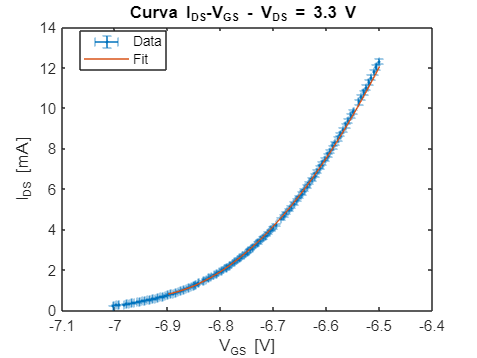


Vdsz(1)=Vds;
knz(1)=k_fit;
dknz(1)=dk_fit;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 3.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=112.3 \pm 0.9$ mA/V$^2$;

- $V_T = -6.95 \pm 0.08$ V;

- $\chi^2_{norm} = 1.9$.

**Misura 2:**

Vd=2 V e Vg tra -7 e -6.4 V (misura 13-9 )

R=150;%ohm
dR=1.5;
Vds=2;
datamat=readmatrix('Data LAB es 13-9');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>-6.9;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit =   96.541496996775550


Vt_fit=-p(2)/2/p(3)

Vt_fit =   -6.915588050510904



for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit =    1.183942197570081


dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit =    0.118684234103570


chi2=chi2n

chi2 =   10.942178545933293


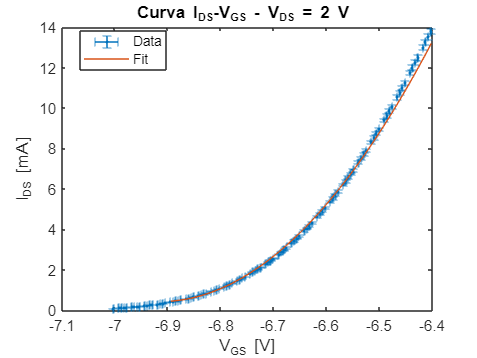


Vdsz(2)=Vds;
knz(2)=k_fit;
dknz(2)=dk_fit;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=96.5 \pm 1.2$ mA/V$^2$;

- $V_T = -6.92 \pm 0.12$ V;

- $\chi^2_{norm} = 10.9$.

### **Curva Id-Vgs con generatore **

Mettiamo Vd = 2.5 (Misura Vdrain = 2.53 V) e Vg tra -7 e -6.35  V

R=150;%ohm
dR=1.5;
Vds=4;
datamat=readmatrix('Data LAB es 13-11');
Vgs=datamat(:,1);
Ids=datamat(:,2);

Vout=Ids/R;

dig_V=20*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>-6.9;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
kexp=60;
Vtexp=2;
pin=[kexp/2*Vtexp^2, -2*kexp/2*Vtexp, kexp/2]';
%modello = @(p,x)(p(1)/2*((x-p(2)).^2));
modello=@(p,x)(p(1)+p(2)*x+p(3)*x.^2);
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p;
k_fit=p(3)*2

k_fit =      1.109715458518837e+02


Vt_fit=-p(2)/2/p(3)

Vt_fit =   -6.924998338574516



for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
dk_fit=2*err_parametri(3)

dk_fit =    1.195024362548564


dp2=err_parametri(2);
dVt_fit=sqrt((dp2/k_fit)^2+(p(2)/k_fit^2*dk_fit)^2)

dVt_fit =    0.104239448105081


chi2=chi2n

chi2 =    8.956166596898274


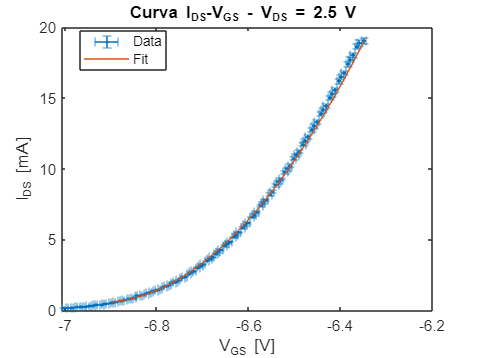


Vdsz(3)=Vds;
knz(3)=k_fit;
dknz(3)=dk_fit;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $K=110.9 \pm 1.2$ mA/V$^2$;

- $V_T = -6.92 \pm 0.10$ V;

- $\chi^2_{norm} = 9$.

Riporto le tre acquisizioni in un unico grafico per valutare meglio:

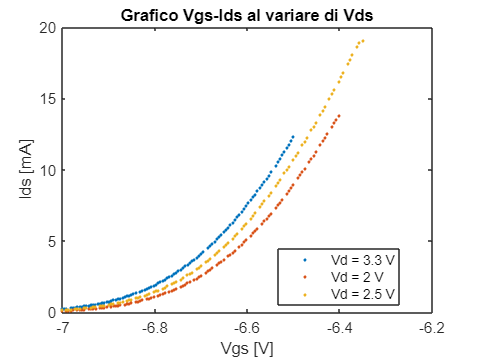

datamat=readmatrix('Data LAB es 13-8');
Vgs1=datamat(:,1);
Ids1=datamat(:,2);
datamat=readmatrix('Data LAB es 13-9');
Vgs2=datamat(:,1);
Ids2=datamat(:,2);
datamat=readmatrix('Data LAB es 13-11');
Vgs3=datamat(:,1);
Ids3=datamat(:,2);

plot(Vgs1, Ids1, '.')
hold on
plot(Vgs2, Ids2, '.')
plot(Vgs3, Ids3, '.')
hold off
title('Grafico Vgs-Ids al variare di Vds')
xlabel('Vgs [V]')
ylabel('Ids [mA]')
legend('Vd = 3.3 V', 'Vd = 2 V', 'Vd = 2.5 V', 'Location', 'best')

Anche con questo modello il risultato non cambia, infatti maggiore è Vds, maggiore è la pendenza della curva.

L'unica differenza con il modello di transistor precedente è quindi la soglia Vt = -6.9 +- 0.1 V , che è negativa.

**Misura della transconduttanza:**

%fit per stimare lambda
[p, dp, chiqn, prod, corr]= fitpoli(1,Vdsz, knz, dknz);
coefficiente=p(1)

coefficiente =    8.087453830082040


dcoefficiente=dp(1)

dcoefficiente =    0.823170926535950


intercetta=p(2)

intercetta =   82.322549547060817


dintercetta=dp(2)

dintercetta =    2.652020477363942


kns=coefficiente;
dkn=dcoefficiente;
lambda=(coefficiente/intercetta)

lambda =    0.098241051505077


dlambda=lambda*sqrt((dcoefficiente/coefficiente)^2+(dintercetta/intercetta)^2)

dlambda =    0.010488227839994


chiqn

chiqn =   25.506957001376101



%misura transconduttanza
Vds= 10; %V
Ids= 25;%mA
gm_manuale2=2*sqrt(0.5*kns*(1+Vds*lambda)*Ids)

gm_manuale2 =   28.313118437168175


dgm2 =    3.022712323212632


gm =     5.6626    5.9366    6.1984    6.4497    6.6915    6.9248    7.1506    7.3695    7.5820    7.7887    7.9901    8.1865    8.3784    8.5659    8.7494    8.9292    9.1054    9.2782    9.4479    9.6146    9.7785    9.9396   10.0982   10.2543   10.4081   10.5597   10.7091   10.8564   11.0018   11.1453   11.2869   11.4268   11.5650   11.7016   11.8366   11.9701   12.1021   12.2327   12.3619   12.4897   12.6163   12.7416   12.8657   12.9886   13.1104   13.2310   13.3505   13.4690   13.5865   13.7029


dgm =     0.6045    0.6338    0.6617    0.6886    0.7144    0.7393    0.7634    0.7868    0.8095    0.8315    0.8530    0.8740    0.8945    0.9145    0.9341    0.9533    0.9721    0.9905    1.0087    1.0265    1.0439    1.0612    1.0781    1.0948    1.1112    1.1274    1.1433    1.1590    1.1746    1.1899    1.2050    1.2199    1.2347    1.2493    1.2637    1.2779    1.2920    1.3060    1.3198    1.3334    1.3469    1.3603    1.3735    1.3867    1.3997    1.4125    1.4253    1.4380    1.4505    1.4629


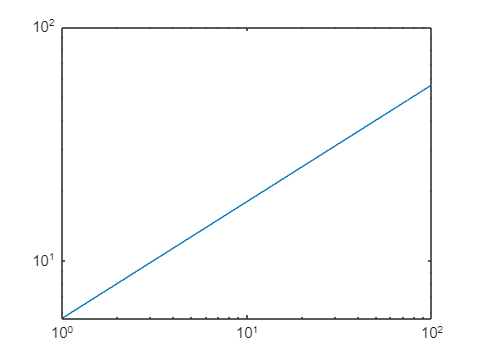

dgm2=gm_manuale2*dlambda/lambda %propago solo dlambda poichè gli altri sono trascurabili

Sul manuale valore tipico è $g_m=$ 55 mS, misurato per $V_{DS} = 10$ V, $I_{DS}$ = 25 mA.

Otteniamo $g_m =28 \pm 3$ mS, che non è compatibile con il valore del datasheet.

# Logbook - Seconda Parte

## Es. 15 - Simulazione con TINA con R2

### **Dipendenza della corrente ai capi di R1 da Vs**

Ci aspettiamo che nella zona lineare $I=\frac{ V_S}{R_1}$

Abbiamo variato Vs tra 0.1 e 10 V

**R1=100 Ohm e R2=330 Ohm**

Con queste resistenze si arriva a saturazione, a I=16.2 mA, per Vs=1.7 V

datamat=readmatrix('Tina es 15 I_R1 vs Vs per R1=100 R2=330', 'DecimalSeparator', ',');
Vs=datamat(:,1);
I=datamat(:,2);
plot(Vs, I*1e3, '.', 'Color','blue')
I=I(1:16);
Vs=Vs(1:length(I));
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vs, I);
coefficiente=p(1);
dcoefficiente=dp(1);
intercetta=p(2);
dintercetta=dp(2);
R=1/coefficiente

R = 100.0053

chiqn;
xx1=linspace(0, max(Vs), 100);
yy1=p(1)*xx1+p(2);

hold on
plot(xx1,yy1*1e3, 'Color','blue')

Resistenza resituita dal fit: 100.005 Ohm

**R1=200 Ohm e R2=330 Ohm**

Con queste resistenze si arriva a saturazione, a I=13.3 mA, per Vs=2.7 V

datamat=readmatrix('Tina es 15 I_R1 vs Vs per R1=200 R2=330.txt', 'DecimalSeparator', ',');
Vs=datamat(:,1);
I=datamat(:,2);
plot(Vs, I*1e3, '.', 'Color','magenta')

I=I(1:27);
Vs=Vs(1:length(I));
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vs, I);
coefficiente=p(1);
dcoefficiente=dp(1);
intercetta=p(2);
dintercetta=dp(2);
R=1/coefficiente

R = 200.6244

chiqn;
xx4=linspace(0, max(Vs), 100);
yy4=p(1)*xx4+p(2);
plot(xx4,yy4*1e3, 'Color','magenta')

Resistenza resituita dal fit: 200.622 Ohm

**R1=330 Ohm e R2=100 Ohm**

Con queste resistenze si arriva a saturazione, a I=16.2 mA, per Vs=5.45 V

datamat=readmatrix('Tina es 15 I_R1 vs Vs per R1=330 R2=100', 'DecimalSeparator', ',');
Vs=datamat(:,1);
I=datamat(:,2);

plot(Vs, I*1e3, '.','Color','red')
I=I(1:54);
Vs=Vs(1:length(I));
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vs, I);
coefficiente=p(1);
dcoefficiente=dp(1);
intercetta=p(2);
dintercetta=dp(2);
R=1/coefficiente

R = 330.1232

chiqn;
xx2=linspace(0, max(Vs), 100);
yy2=p(1)*xx2+p(2);
plot(xx2,yy2*1e3,'Color','red')

Resistenza resituita dal fit: 330.12 Ohm

**R1=330 Ohm e R2=330 Ohm**

Con queste resistenze si arriva a saturazione, a I=10.6 mA, per Vs=3.6 V

datamat=readmatrix('Tina es 15 I_R1 vs Vs per R1=330 R2=330.txt', 'DecimalSeparator', ',');
Vs=datamat(:,1);
I=datamat(:,2);
plot(Vs, I*1e3, '.', 'Color','#EDB120')
I=I(1:35);
Vs=Vs(1:length(I));
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vs, I);
coefficiente=p(1);
intercetta=p(2);
R=1/coefficiente

R = 330.0326

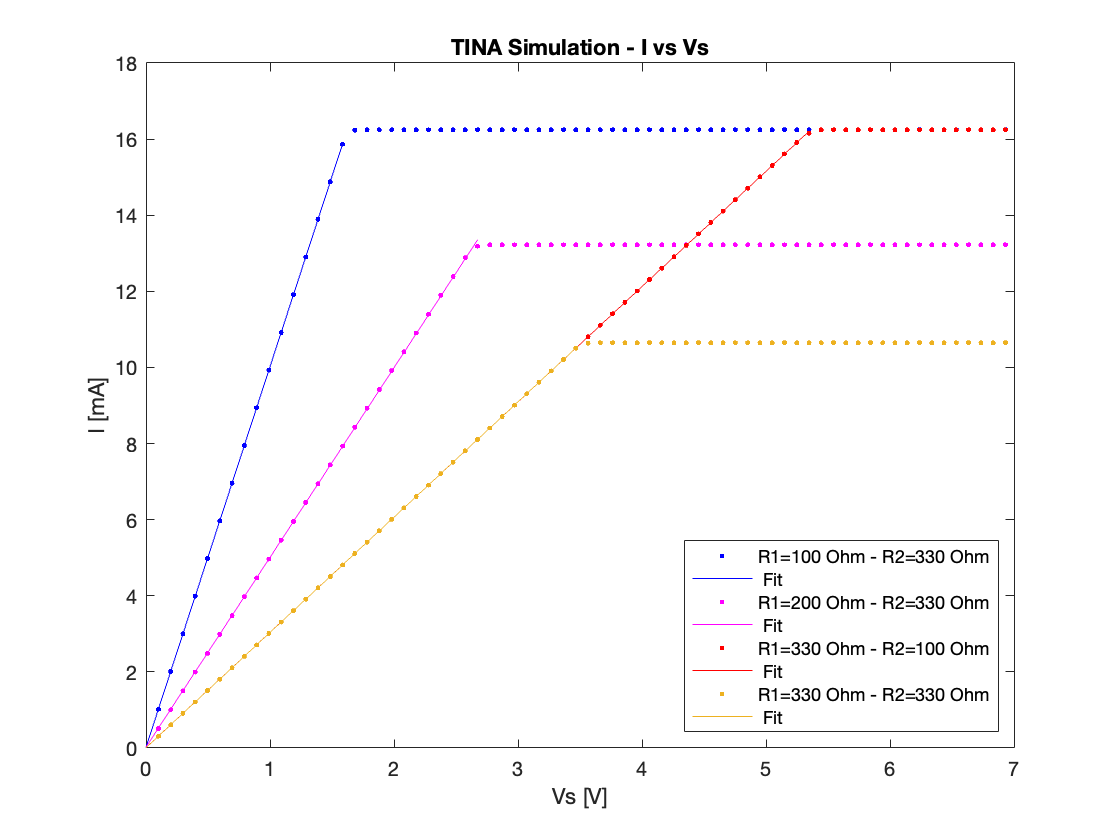

chiqn;
xx3=linspace(0, max(Vs), 100);
yy3=p(1)*xx3+p(2);
plot(xx3,yy3*1e3, 'Color','#EDB120')
hold off


title('TINA Simulation - I vs Vs')
xlabel('Vs [V]')
ylabel('I [mA]')
xlim([0,7]);
legend('R1=100 Ohm - R2=330 Ohm', ' Fit','R1=200 Ohm - R2=330 Ohm',' Fit', 'R1=330 Ohm - R2=100 Ohm',' Fit','R1=330 Ohm - R2=330 Ohm',' Fit', 'location','southeast')

Resistenza resituita dal fit: 330.033 Ohm

Si vede dai vari fit che il coefficiente angolare è esattamente 1/R1 come atteso, mentre la tensione Vs a cui inizia la saturazione, e di conseguenza la corrente per cui si ha saturazione, aumenta al diminuire del rapporto ${R_2}{/R_1}$. 

Infatti, $V_{Drain} = 12$ V costante,  $V_{Source} = V_S \left(1+{R_2}/{R_1}\right)$, e $V_{Gate}$ aumenta linearmente con $V_S$, quindi $V_{GS}$ sale sopra la soglia della saturazione per valori più grandi di $V_S$ al diminuire di $R_2 / R_1$. 

Nel grafico sotto riportiamo l'andamento del valore di $V_S$ per cui il transistor arriva a saturazione al variare del rapporto $R_2/R_1$.

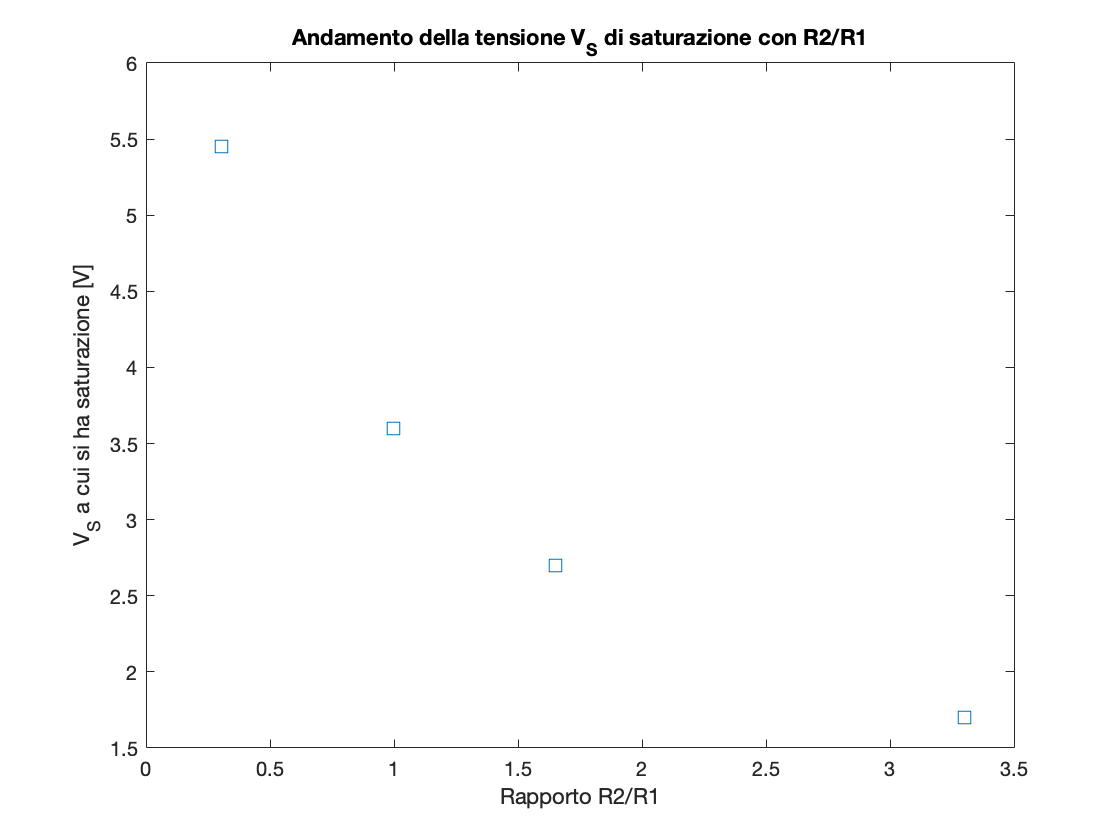

Vsat=[1.7, 5.45, 3.6, 2.7];
R1=[100, 330, 330, 200];
R2=[330, 100, 330, 330];
plot(R2./R1, Vsat, 's', 'MarkerSize',8)
xlabel('Rapporto R2/R1')
ylabel('V_S a cui si ha saturazione [V]')
title('Andamento della tensione V_S di saturazione con R2/R1')
ylim([1.5, 6])

### **Dipendenza della corrente ai capi di R1 da R1**

Ci aspettiamo che nella zona lineare $I=\frac{ V_S}{R_1}$

Abbiamo variato R1 tra 10 Ohm e 1 kOhm e fissato Vs a 5 V e R2 a 330 Ohm

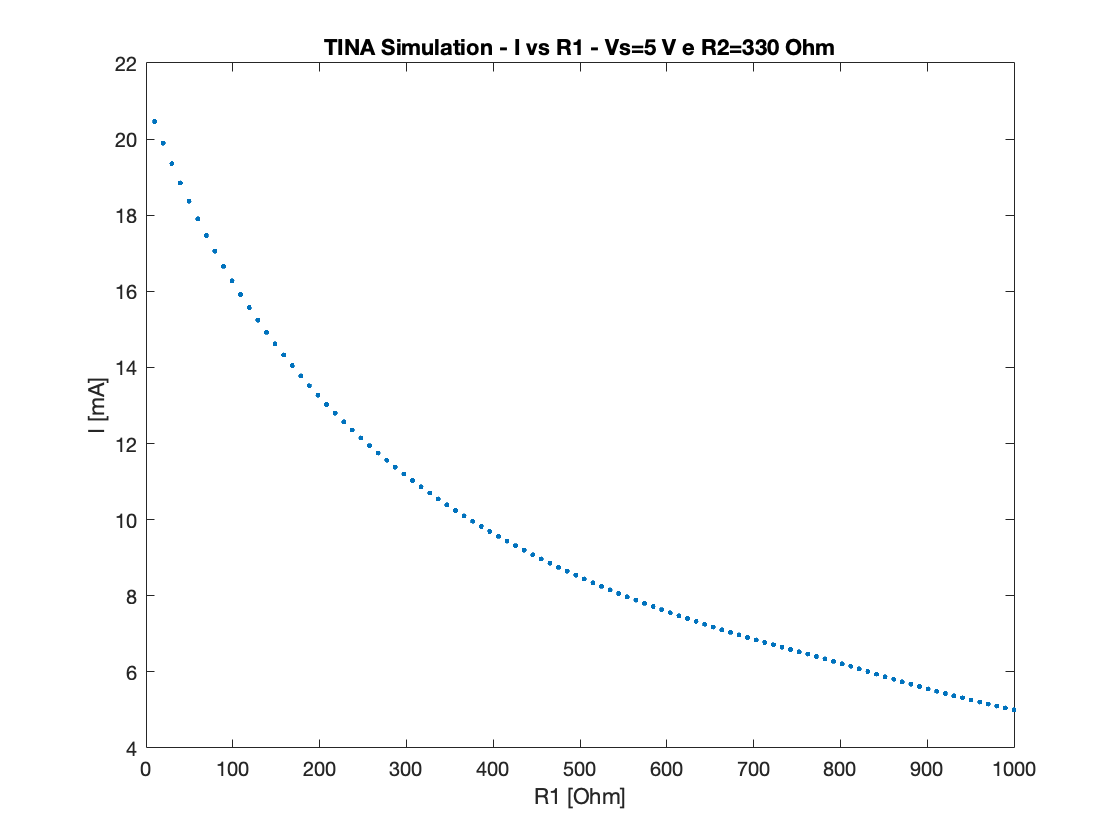

datamat=readmatrix('Tina es 15 I_R1 vsR1 per Vs=5 R2=330.txt', 'DecimalSeparator', ',');
R=datamat(:,1);
I=datamat(:,2);
plot(R, I*1e3, '.')


title('TINA Simulation - I vs R1 - Vs=5 V e R2=330 Ohm')
ylabel('I [mA]')
xlabel('R1 [Ohm]')

Si vede che la corrente diminuisce all'aumentare di R1. L'andamento però non è del tipo $1/R_1$, soprattutto per i valori più bassi di $R_1$.

### **Dipendenza di Vsource da R2**

Abbiamo variato R2 tra 10 Ohm e 1 kOhm e simulato per diversi valori di R1 e impostando Vs a 5 V.

Andamento atteso: 

$V_{Source} = V_S \left(1+R_2/R_1\right)$ nel regime lineare, finché non si arriva alla saturazione. 

**R1=100 Ohm e Vs = 5V - Simulazione di Vsource**

datamat=readmatrix('Tina es 15 Vsource vsR2 per Vs=5 R1=100.txt', 'DecimalSeparator', ',');
R2=datamat(:,1);
Vsource=datamat(:,2);
plot(R2, Vsource, '.')


**R1=330 Ohm e Vs = 5V - Simulazione di Vsource**

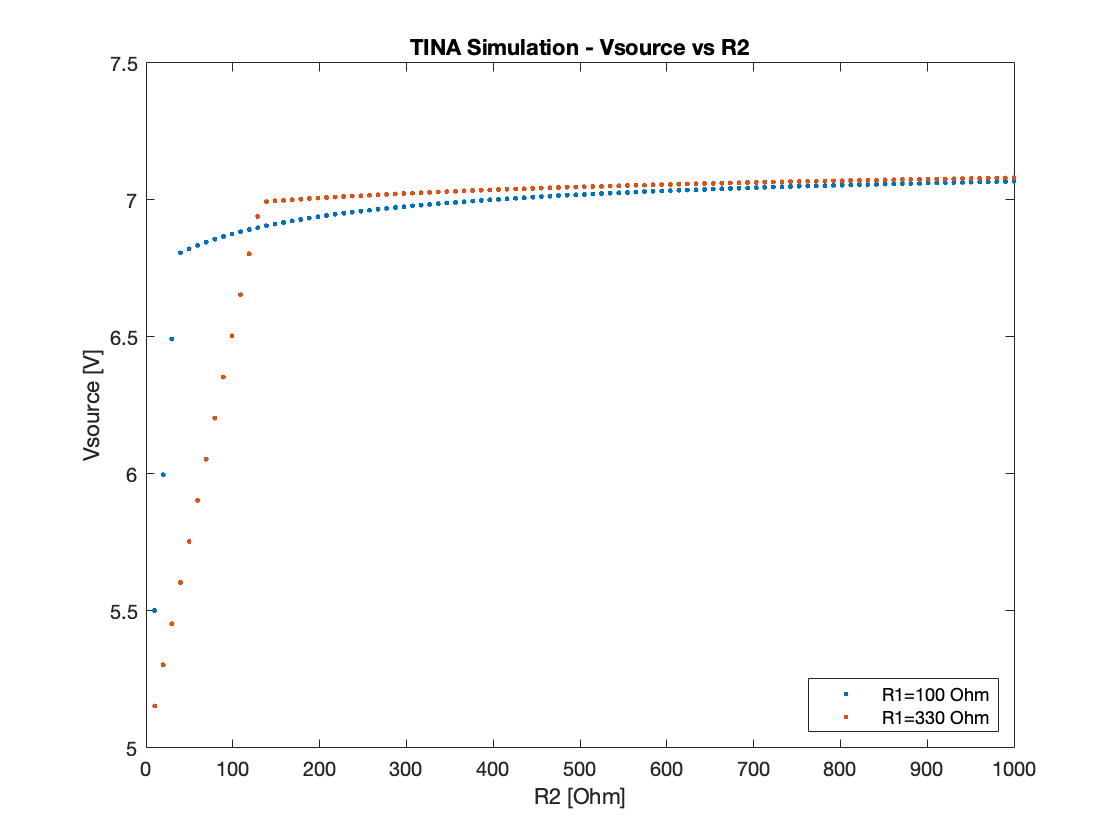

datamat=readmatrix('Tina es 15 Vsource vsR2 per Vs=5 R1=330.txt', 'DecimalSeparator', ',');
R2=datamat(:,1);
Vsource=datamat(:,2);
hold on 
plot(R2, Vsource, '.')
hold off
legend('R1=100 Ohm',  'R1=330 Ohm', 'location','southeast')
title('TINA Simulation - Vsource vs R2')
xlabel('R2 [Ohm]')
ylabel('Vsource [V]')

Si vede che $V_{Source}$ aumenta linearmente con $R_2$ finché non arriva a 7 V, poi si ferma perché il transistor è arrivato in saturazione.

$V_{Gate}$ è costante perché $V_S$ è costante e $V_{Drain}$ è fissa a 12 V, quindi l'unica tensione variabile è $V_{Source}$ e si arriva in saturazione quando $V_{DS}$ è sufficientemente alta rispetto a $V_{GS}$. Questo passaggio di regime si ha per $V_{Source} = 7$ V e questo valore non dipende dalle resistenze usate. 

### **Dipendenza della corrente ai capi di R1 e di Vsource da R2**


$$I = \frac{V_{Source}-V_S}{R_2}$$


Quando il transistor è in regime lineare, $I R_2 = V_{Source}-V_S = V_{S} R_2/R_1$, quindi $I = V_S/R_1$ costante al variare di $R_2$.

Quando invece $V_{Source}$ raggiunge la saturazione, si ha che $V_{Source}-V_S$ è costante e I decresce come 1/R2.

**R1=100 Ohm e Vs = 5V - Simulazione di I**

Vs=5;
R1=100;
datamat=readmatrix('Tina es 15 I_R1 vsR2 per Vs=5 R1=100.txt', 'DecimalSeparator', ',');
R2=datamat(:,1);
I=datamat(:,2);

plot(R2, I*1e3, '.', 'Color','blue')
hold on 
xx1=linspace(0, 1000, 10);
yy1=ones(1, 10)*Vs/R1;
plot(xx1, yy1*1e3, '--', 'Color','#4DBEEE')

**R1=330 Ohm e Vs = 5V - Simulazione di I**

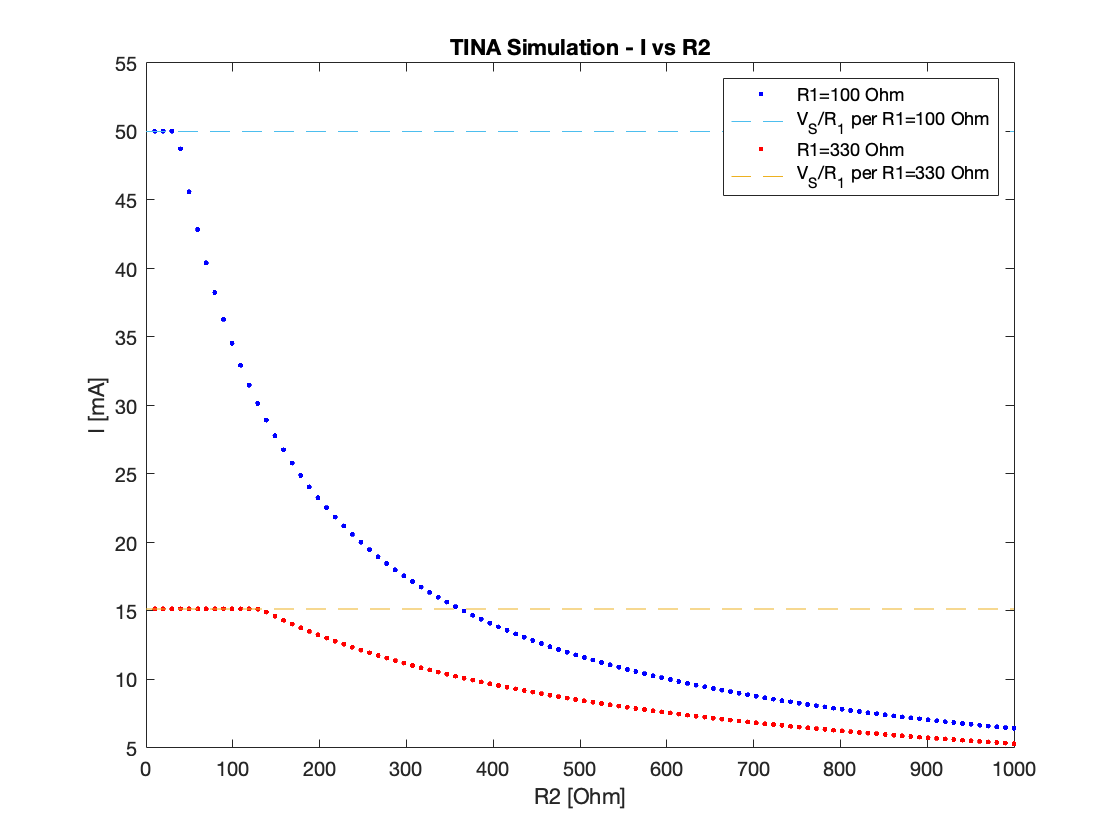

R1=330;
datamat=readmatrix('Tina es 15 I_R1 vsR2 per Vs=5 R1=330.txt', 'DecimalSeparator', ',');
R2=datamat(:,1);
I=datamat(:,2);

plot(R2, I*1e3, '.', 'Color','red')
xx1=linspace(0, 1000, 10);
yy1=ones(1, 10)*Vs/R1;

plot(xx1, yy1*1e3, '--', 'Color','#EDB120')
hold off
legend('R1=100 Ohm', 'V_S/R_1 per R1=100 Ohm',  'R1=330 Ohm', 'V_S/R_1 per R1=330 Ohm','location','northeast')
title('TINA Simulation - I vs R2')
xlabel('R2 [Ohm]')
ylabel('I [mA]')

## Es. 16 - Simulazione con TINA con LED

Abbiamo sostituito a R2 un LED, in particolare il modello LN1851C, che ha $\lambda_{peak} = 630$ nm e abbiamo impostato manualmente $I_{F,max}$ a 30 mA, in modo che avesse un comportamento simile a LED LA 3366 usato nella maggior parte delle misure successive.

Abbiamo impostato R1 a 330 Ohm, in modo che la corrente massima che scorre nel circuito rimanesse sempre sotto i 20 mA.

**Dipendenza di I da Vs**

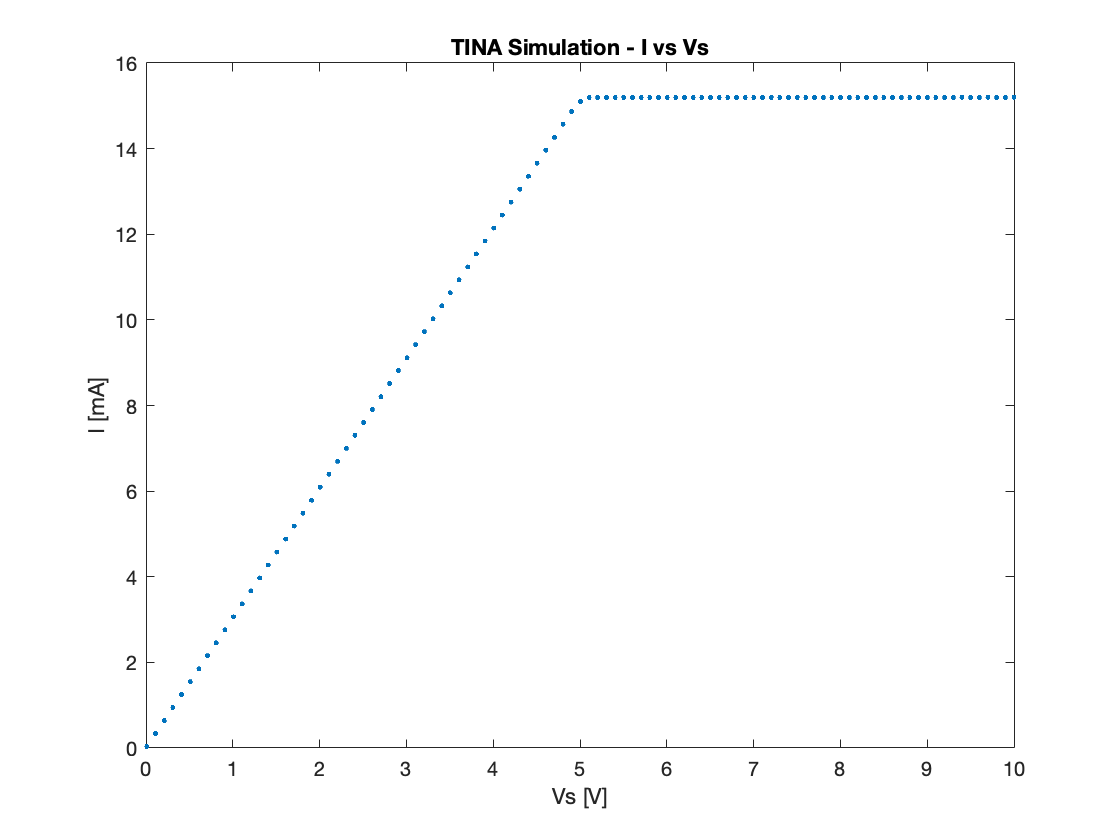

datamat=readmatrix('Tina es 16 I_R1 vs Vs per R1=330.txt', 'DecimalSeparator', ',');
Vs=datamat(:,1);
I=datamat(:,2);
plot(Vs, I*1e3, '.')
title('TINA Simulation - I vs Vs')
xlabel('Vs [V]')
ylabel('I [mA]')

Si vede un andamento uguale alle misure dell'esercizio precedente: la corrente è proporzionale a Vs e il coefficiente angolare è 1/R1. A Vs=5 V I arriva a saturazione, rimanendo costante a 15 mA.

**Dipendenza di Vsource da Vs**

Equazioni per trovare la relazione tra $V_{source}$ e $V_{in}$ prima della saturazione: 


$$V_{S} = I R_1$$



$$I = I_{S} \left(e^{(V_{source}-V_{S} )/ k}-1\right) = \frac{V_{S}}{R_1}$$


Si ricava quindi $V_{source} = V_{S} +k\ln\left( \frac{V_{S}}{I_S R_1}+1\right)$. 

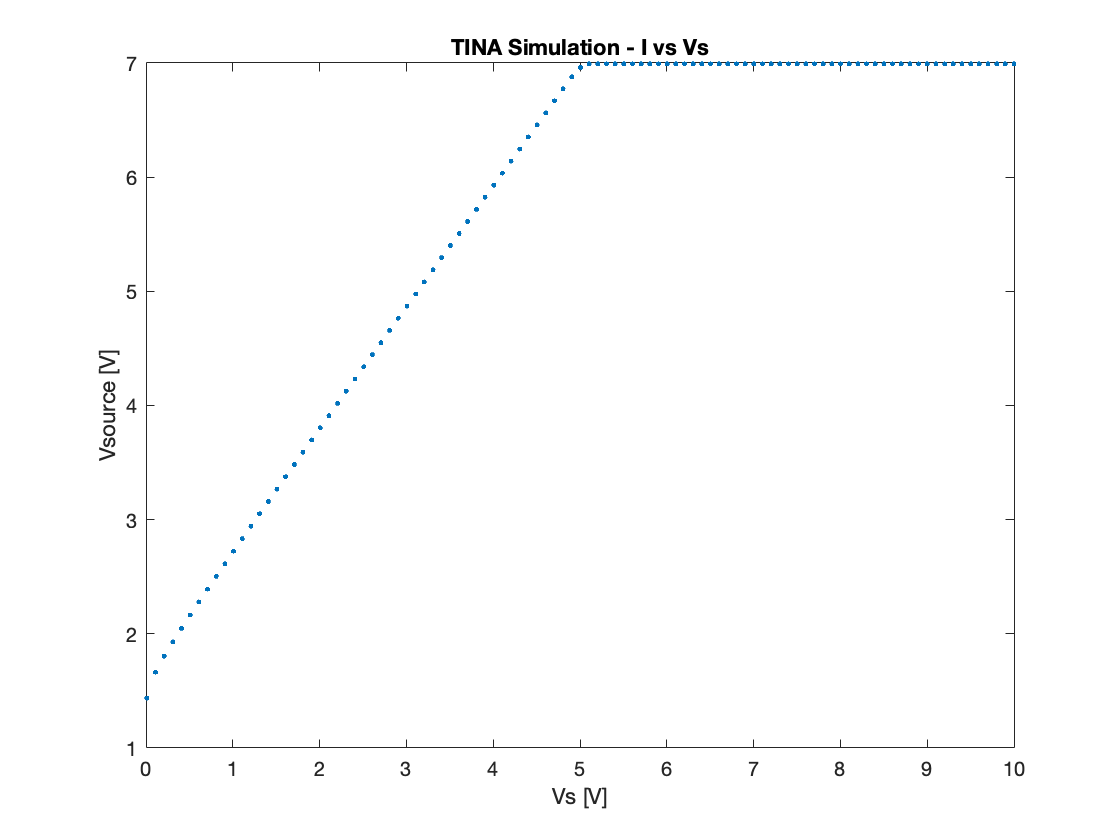

datamat=readmatrix('Tina es 16 Vsource vs Vs per R1=330.txt', 'DecimalSeparator', ',');
TINA_Vs=datamat(:,1);
TINA_V=datamat(:,2);
plot(TINA_Vs, TINA_V, '.')
title('TINA Simulation - I vs Vs')
xlabel('Vs [V]')
ylabel('Vsource [V]')

## Es. 17/18/19 - circuito con R2

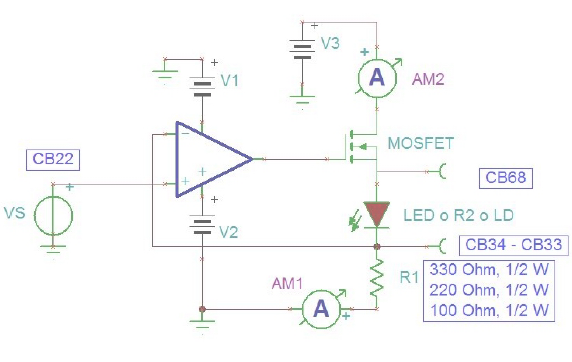

Montato il circuito nel seguente modo:

- R1 = R2 = 330 Ohm;

- OpAmp ua741 alimentato con $$\pm$$12 V;

- V3 = 12 V;

- Mosfet BS170.

Dopo aver visto qualitativamente la risposta del circuito a vari Vs con Traccia_Vin_Vout_2C, abbiamo utilizzato Traccia_Vin_Vout_diff per acquisire più misure variando Vs:

- Fondo scala 10 V per tutti i canali (CB68, CB33 e CB34, posizionati come in figura);

- Vs da 0.25 a 3.75 V;

- N misure = 50. 

Abbiamo $V_{in}=V_S$, le  tensioni nei canali CB68 (tensione di Source) e CB33/CB34 (tensione ai capi di $R_1$). 

Facciamo variare Vs da 0.25 V a 3.75 V, in modo da avere $V_{Gate}>V_T$ e da non arrivare in saturazione.

R1=330;%ohm
dR1=3.3;
R2=330;%ohm
dR2=3.3;
datamat=readmatrix('Data LAB es 17 Vs CB33');
Vs=datamat(:,1);
Vr1=datamat(:,2); %potenziale a CB33/34

dVs=ones(1, length(Vs))*20/(2^(12)); %errore di digitalizzazione
dVr1=ones(1, length(Vr1))*20/(2^(12)); %errore di digitalizzazione

%misura ddp ai capi di R2
datamat=readmatrix('Data LAB es 17');
Vsource=datamat(:,1); %potenziale a CB68
Vs1=datamat(:,2); %potenziale a CB33/34

dVsource=ones(1, length(Vsource))*20/(2^(12)); %errore di digitalizzazione
dVs1=ones(1, length(Vs1))*20/(2^(12)); %errore di digitalizzazione

%fit sulle prime misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vs, Vr1, dVr1');
coefficiente=p(1)

coefficiente = 0.9999

dcoefficiente=dp(1)

dcoefficiente = 6.6992e-04

intercetta=p(2)

intercetta = 0.0012

dintercetta=dp(2)

dintercetta = 0.0015

chiquadro=chiqn

chiquadro = 0.1508

xx=linspace(min(Vs), max(Vs), 1000);
yy=p(1)*xx+p(2);

%fit sulle seconde misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vsource, Vs1, dVs1');
coefficiente2=p(1)

coefficiente2 = 1.9984

dcoefficiente2=dp(1)

dcoefficiente2 = 6.2526e-04

intercetta2=p(2)

intercetta2 = 0.0032

dintercetta2=dp(2)

dintercetta2 = 0.0015

chiquadro2=chiqn

chiquadro2 = 0.3635

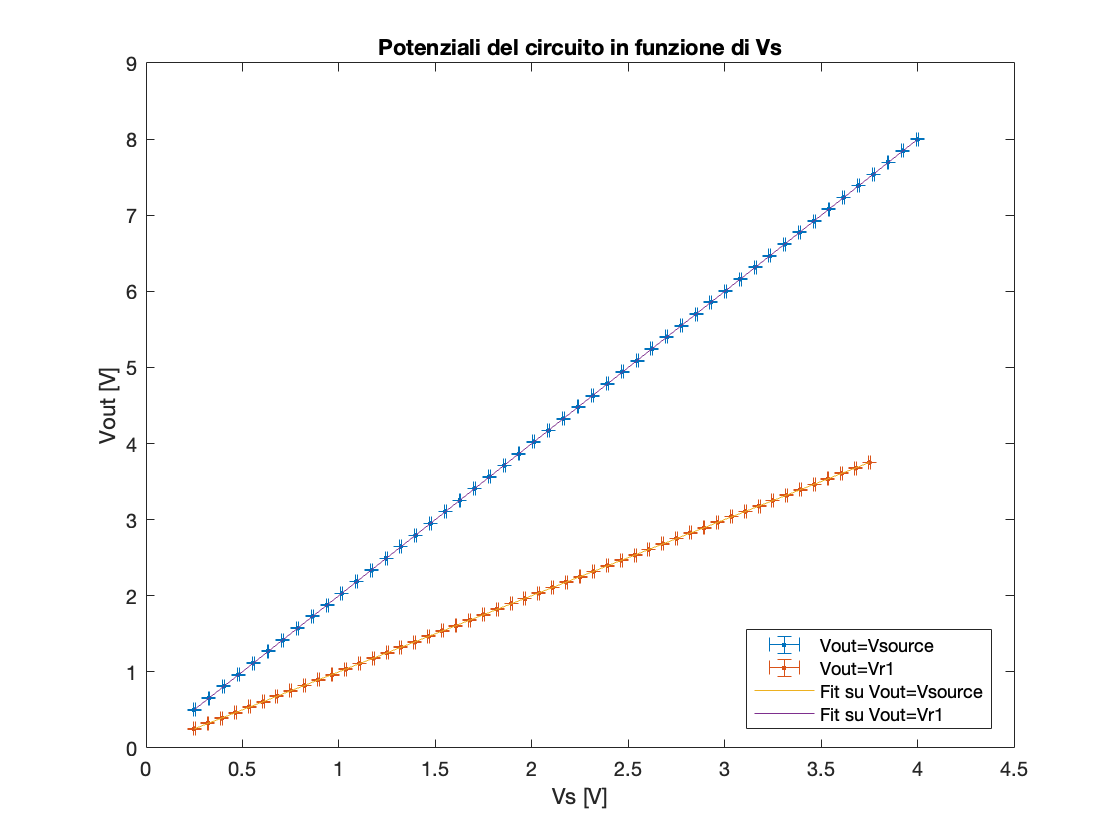

xx2=linspace(min(Vsource), max(Vsource), 1000);
yy2=p(1)*xx2+p(2);


%Grafici
errorbar(Vsource, Vs1, dVsource, dVsource, dVs1, dVs1, '.') %grafico di Vs in funzione di Vc (CB33/34)
hold on
errorbar(Vs, Vr1, dVs, dVs, dVr1, dVr1, '.') %grafico di Vsource a CB68 in funzione di Vs (CB33/34)
plot(xx, yy)
plot(xx2, yy2)
hold off
title('Potenziali del circuito in funzione di Vs')
xlabel('Vs [V]')
ylabel('Vout [V]')
legend('Vout=Vsource', 'Vout=Vr1', 'Fit su Vout=Vsource', 'Fit su Vout=Vr1', 'Location', 'best')

Risultati fit lineare su Vs-Vr1 (dove Vr1 è CB33/34):

- coefficiente angolare = 0.9999 $$\pm$$ 0.0006;

- intercetta = (1.2 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.15.

Risultati fit lineare su Vs-Vsource (dove Vsource è CB68):

- coefficiente angolare = 1.9984 $$\pm$$ 0.0006;

- intercetta = (3.2 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.36

Entrambi i fit riportano un'intercetta che possiamo assumere come nulla.

Con il primo fit troviamo $V_{S}=V_{R1}$, almeno nel range tensioni testato.

Dal secondo fit invece vediamo $V_{Source}=2 \cdot V_{S}$.

Possiamo spiegare entrambi i comportamenti con le regole d'oro dell'OpAmp:

Dovendo essere le ddp agli ingressi negativo e positivo dell'amplificatore uguali, abbiamo che $V_{S}=V_{R1}$, che è compatibile con le misure prese; d'ora in poi useremo $V_{S}$ per indicare entrambi. Inoltre la corrente che attravera $R_{2}$ è la stessa che attraversa $R_{1}$, in quanto non deve esserci corrente che attraversa gli ingressi dell'OpAmp. Abbiamo dunque $I_{2}=I_{1}=V_{S}/R_{1}$, che dalla legge di Ohm deve essere $I_{2}=\frac{V_{Source}-V_{S}}{R_{1}}$. Ponendo uguali i risultati e risolvendo l'equazione si trova $V_{S}=\frac{V_{Source }  \cdot R_{1}}{R_{1}+R{2}}$.

Avendo preso $R_{1}=R_{2}$ ci aspettiamo dunque che $V_{Source}=2 \cdot V_{S}$, che è compatibile con le misure prese.

## Es. 20 - Vsource al variare di Vs

Facciamo variare Vs da 0.25 a 3.75 V in 50 punti, altrimenti Vgate supera il fondo scala.

Fondi scala 10 V

Misurando insieme CB68 e CB33 i segnali appaiono distorti, hanno una variazione di pendenza a voltaggi variabili. Abbiamo risolto il problema: CB33 e CB34 non erano collegati correttamente.

R1=R2=330 Ohm (1% toll.).

R1=330;%ohm
dR1=3.3;
datamat=readmatrix('Data LAB es 20');
Vs=datamat(:,1);
Vsource=datamat(:,2); %potenziale a CB68

dVs=ones(1, length(Vs))*20/(2^(12)); %errore di digitalizzazione
dVsource=ones(1, length(Vsource))*20/(2^(12)); %errore di digitalizzazione

%fit sulle prime misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vs, Vsource, dVsource');
coefficiente=p(1)

coefficiente = 2.0000

dcoefficiente=dp(1)

dcoefficiente = 6.6992e-04

intercetta=p(2)

intercetta = 0.0030

dintercetta=dp(2)

dintercetta = 0.0015

chiquadro=chiqn

chiquadro = 0.4685

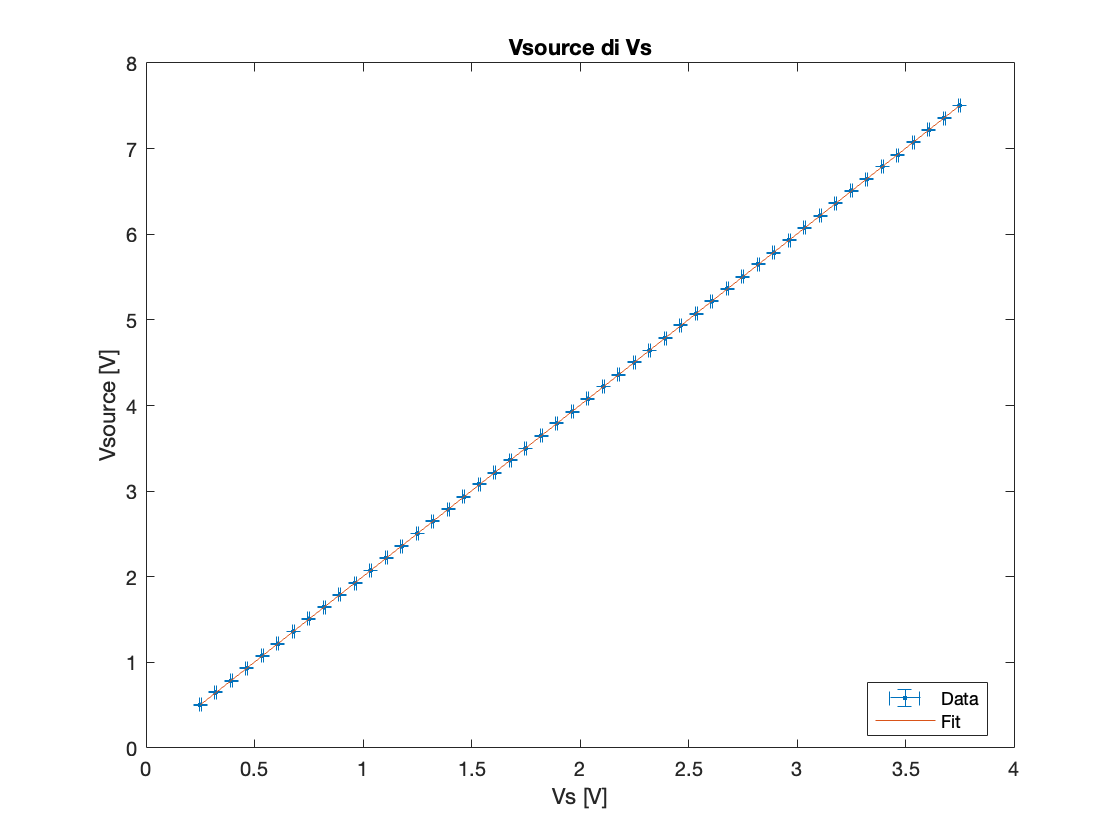

xx=linspace(min(Vs), max(Vs), 1000);
yy=p(1)*xx+p(2);

%Grafici
errorbar(Vs, Vsource, dVs, dVs, dVsource, dVsource, '.') %grafico di Vsource in funzione di Vs (CB68)
hold on
plot(xx, yy)
hold off
title('Vsource di Vs')
xlabel('Vs [V]')
ylabel('Vsource [V]')
legend('Data', 'Fit', 'Location', 'best')

Risultati fit lineare su Vs-Vr1:

- coefficiente angolare = 2.0000 $$\pm$$ 0.0007;

- intercetta = (0.3 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.47.

Le misure sono compatibili con il risultato atteso dalla relazione che lega Vsource a Vs, ricavata nell'esercizio precedente.

## Es. 21- LED al posto di R2

Abbiamo scelto di usare il LED LA 3366 e lo abbiamo messo al posto di $R_2$(l'anodo è la stanghetta più lunga).

Misuriamo con Vin_Vout_2C, la tensione dell'anodo del LED, facendo variare Vs da 0.25 V a 3.75 V, in modo da avere $V_{Gate}>V_T$ e da non arrivare in saturazione o superare il fondoscala.

Abbiamo usato come fondo scala sempre 10 V.

La tensione dell'anodo è uguale alla tensione del Source. 

Equazioni per trovare la relazione tra $V_{source}$ e $V_{in}$: 


$$V_{in} = I R_1$$



$$I = I_{S} \left(e^{(V_{source}-V_{in} )/ k}-1\right) = \frac{V_{in}}{R_1}$$


Si ricava quindi $V_{source} = V_{in} +k\ln\left( \frac{V_{in}}{I_S R_1}+1\right)$. 

Facciamo inizialmente, dopo aver visto che i dati si dispongono approssimativamente su una retta, l'approssimazione che il secondo termine sia circa costante (variazioni molto minori di $V_{in}$) al variare di $V_{in}$, che verifichiamo a posteriori, dopo aver avuto una stima di $k$ e $I_S$. Quindi si approssima che $V_{source}$ dipenda da $V_{in}$ in modo lineare. 

R=330;%ohm
dR=3.3;
datamat=readmatrix('Data LAB es 21');
Vin=datamat(:,1);
Vsource=datamat(:,2);
Vcb33=datamat(:,3);
dig_V=20*2^(-12); %digitalizzazione
Vin_fit=Vin(1:length(Vin));
Vsource_fit=Vsource(1:length(Vin_fit));


dV=dig_V*ones(length(Vin_fit), 1);

errorbar(Vin_fit, Vsource_fit, dV, dV, '.')
title('Curva V_{source} vs V_{S} - LA 3366')
ylabel('V_{source} [V]')
xlabel('V_{S} [V]')



Facciamo un fit lineare per vedere quanto valgono coefficiente e intercetta

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vin_fit, Vsource_fit, dV);
coefficiente=p(1)

coefficiente = 1.0281

dcoefficiente=dp(1)

dcoefficiente = 6.6992e-04

intercetta=p(2)

intercetta = 1.7780

dintercetta=dp(2)

dintercetta = 0.0015

chiqn

chiqn = 2.3467

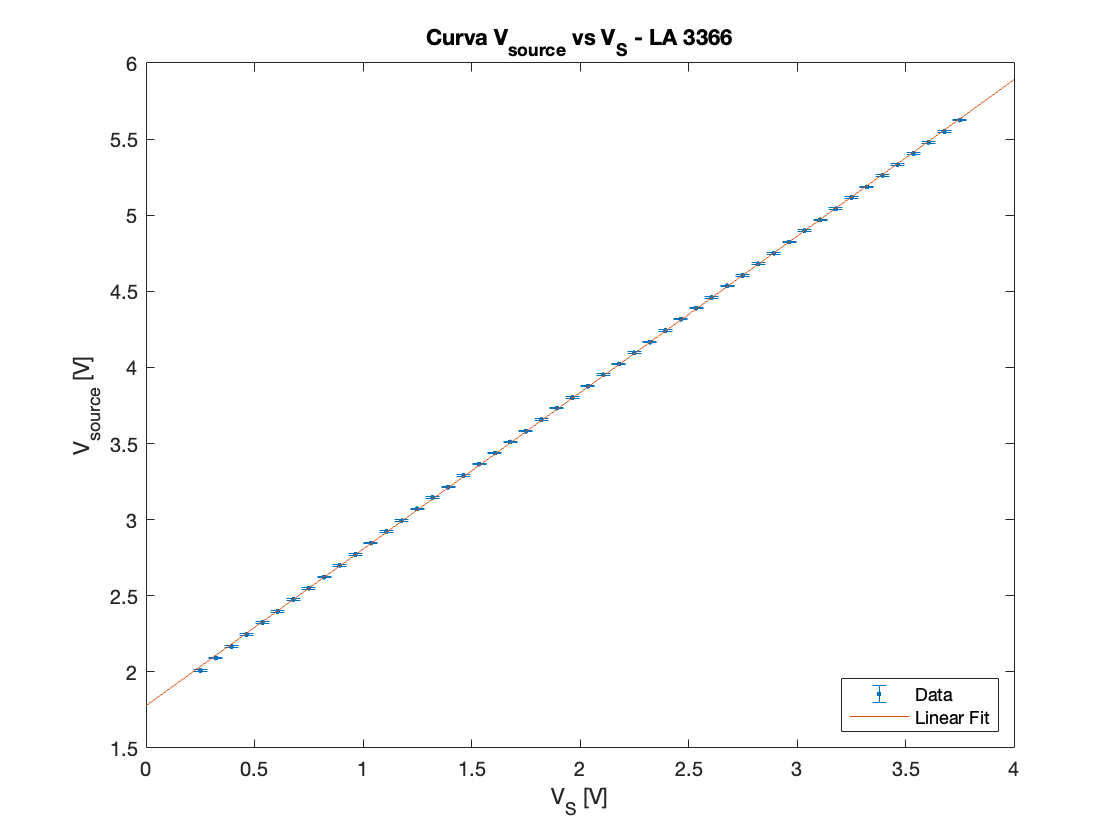

xx=linspace(0, 4, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy)
hold off
legend('Data', 'Linear Fit', 'Location','southeast')

Risultati del fit lineare: 

- coefficiente = $1.028 \pm 0.007$;

- intercetta = $1.778 \pm 0.002$ V;

- $\chi^2_{norm} = 2.3$.

La corrente che scorre nel led è proporzionale alla tensione di ingresso, perché la tensione ai capi di $R_1$ è proprio uguale a $V_S$. Dal fit sembra che il modello lineare sia abbastanza adeguato, visto il chi quadro normalizzato di 2.3.

**Curva I-V del LED da queste misure**

Da queste misure si può ricavare la curva caratteristica del led nel seguente modo: 


$$V_{catodo} = V_{in}$$

$$= I_{DS} R_1$$
  


$$V_{anodo} = V_{source}$$


$\Delta V_{LED} = V_{source}-V_{in}$  e $I_{LED} = \frac{V_{in}}{R}$

Modello di fit: $I(V) = I_S   \cdot \left(e^{kV}-1\right)$, con $k=\frac{1}{\eta V_T}$ e $V_T \simeq 25$ mV

Abbiamo provato all'inizio con tre parametri ($I_S$, un coefficiente all'esponenziale e un offset), però l'offset viene 0 con incertezza nulla, quindi lo abbiamo eliminato dal fit, e il coefficiente all'esponenziale viene sempre quasi uguale al valore impostato nei parametri iniziali e il fit restituisce un messaggio di errore sul fatto che lo Jacobiano è nullo. 

Abbiamo deciso quindi di dare come unico parametro di fit $I_S$, cambiando a mano il valore per k che minimizzasse il chi quadro.

V=Vsource-Vcb33;
I=Vin/R;

dVdig=20*2^(-12);
dV=dVdig*ones(length(V), 1);
dI=sqrt((Vin*dR/R^2).^2+(dV/R).^2);

pin=[4.5e-10]';
eVt=44.36

eVt = 44.3600

modello = @(p,x)(p(1)*(exp(x*1/eVt*1e3)-1));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(V, I,modello, pin, 'Weights', dI.^(-2));
%eVT_mV=1/p(2)*1e3
Is=p(1)

Is = 5.7281e-21

dIs=sqrt(COVB(1,1))

dIs = 4.8436e-23


chisq_norm=chi2n

chisq_norm = 30.6644

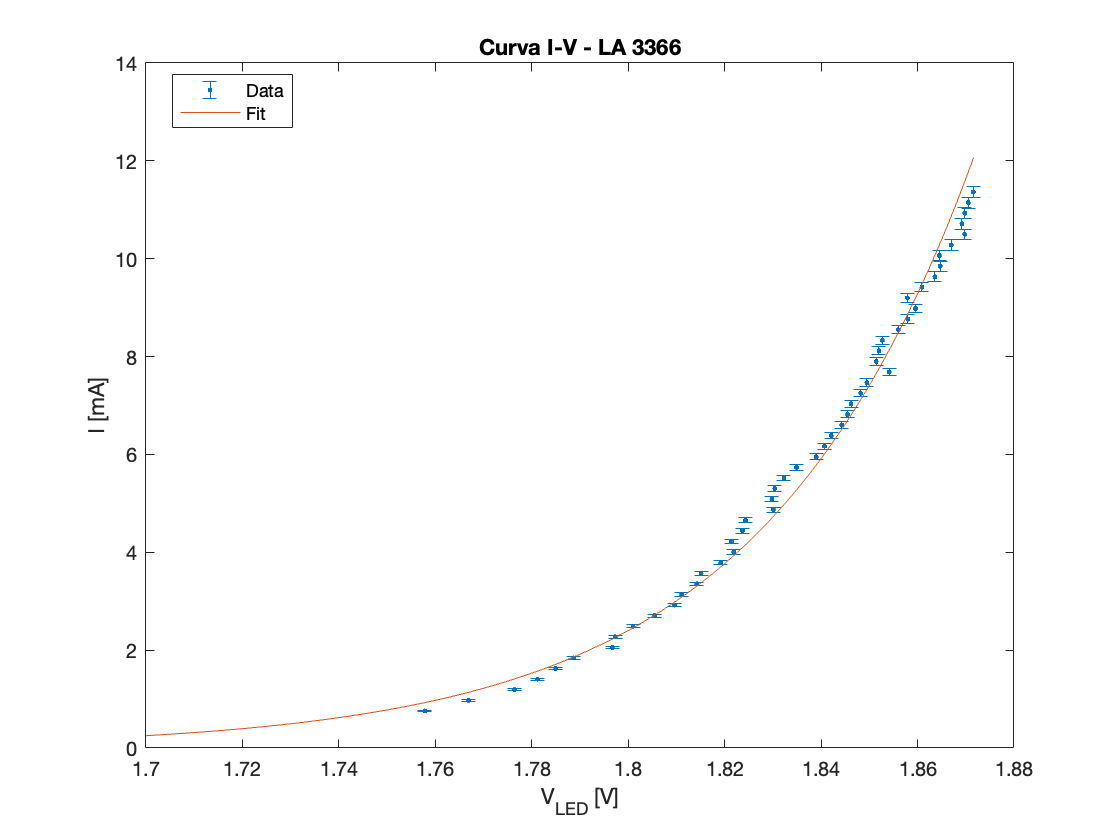

xx=linspace(1.7,max(V), 1000);
yy=(p(1)*(exp(xx*1/eVt*1e3)));
errorbar(V,I*1e3, dI*1e3, dI*1e3, '.')
hold on
plot(xx,yy*1e3)
hold off
title('Curva I-V - LA 3366')
ylabel('I [mA]')
xlabel('V_{LED} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit: 

- $k=$$\eta V_T = 44.36$ mV

- $I_S = (5.73 \pm 0.04) \cdot 10^{-21}$ A

- 
$$\chi^2_{norm} = 31$$


**Verifica dell'approssimazione fatta nel fit lineare**

Verifica numerica che l'approssimazione fatta sopra, cioè che $k\ln\left( \frac{V_{in}}{I_S R_1}+1\right)$ approssimabile a una costante.

Dal fit, si ha $I_S = 5.73 \cdot 10^{-21}$ A e $k = 44.36$ mV.

0.04436*log(1+min(Vin)/(5.8*1e-21*330));
0.04436*log(1+max(Vin)/(5.8*1e-21*330));

$k\ln\left( \frac{V_{in}}{I_S R_1}+1\right)$ per $V_{in}$ tra 0.25 e 3.75 V varia tra 1.75 V e 1.87 V, cioè la sua variazione è dell'ordine di 0.1 V, trascurabile per i valori più alti di $V_{in}$, ma non per quelli iniziali. Quindi non è un'approssimazione valida e si spiega così il fatto che il coefficiente angolare non è 1 come atteso. 

Si vede però che l'intercetta stimata dal fit ($1.778 \pm 0.002$ V ) rientra nell'intervallo individuato per $k\ln\left( \frac{V_{in}}{I_S R_1}+1\right)$. 

Se si restringe l'intervallo di punti su cui viene fatto il fit lineare, prendendo valori sempre crescenti di $V_{in}$, l'intercetta sale sempre di più, rimanendo però tra 1.75 V e 1.87 V. 

Abbiamo fatto un fit della differenza $V_{source}-V_{CB33}$ al variare di $V_{in}$, usando un solo parametro libero, Is, perché se inseriamo anche $k$ Matlab ci dà messaggio di errore e resistuisce come valore il parametro iniziale impostato per $k$. 

Abbiamo invece inserito $k$ come costante, usando il valore trovato nel fit della curva I-V, $k = 44.36$ mV.

V1=Vsource-Vcb33;
dV1=dV*sqrt(2);
pin=[Is]';
modello = @(p,x)(eVt*1e-3*log(x/p(1)/R+1));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vin, V1,modello, pin, 'Weights', dV.^(-2));

Isat=p(1)

Isat = 5.7032e-21

dIsat=sqrt(COVB(1,1))

dIsat = 5.5530e-23


chisq_norm=chi2n

chisq_norm = 0.3878

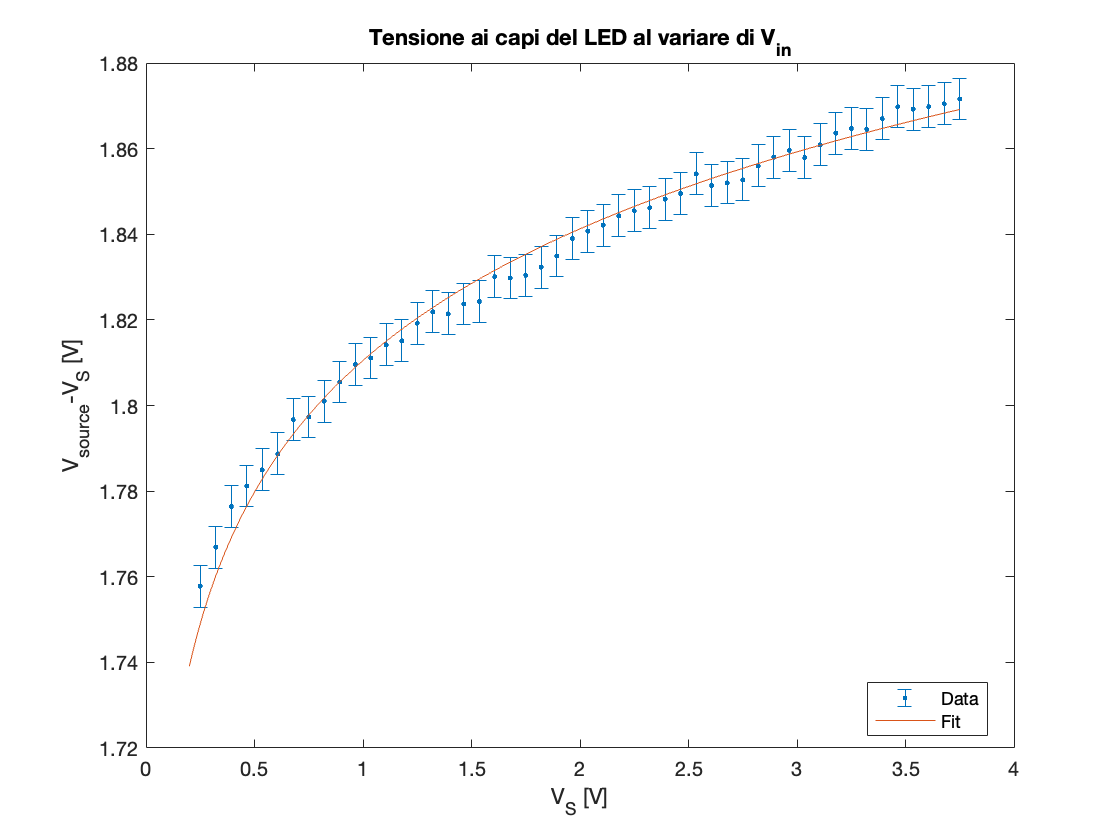

xx=linspace(0.2,max(Vin), 1000);
yy=(eVt*1e-3*log(xx/p(1)/R+1));
errorbar(Vin, V1, dV, dV,'.')
hold on
plot(xx,yy)
hold off
title('Tensione ai capi del LED al variare di V_{in}')
ylabel('V_{source}-V_{S} [V]')
xlabel('V_{S} [V]')
legend('Data', 'Fit', 'Location','best')

Risultati del fit logaritmico:

- $I_S=(5.70 \pm 0.06) \cdot 10^{-21}$ A

- 
$$\chi^2_{norm} = 0.4$$


Si vede quindi che $V_{source}-V_{in}$ ha andamento logaritmico come previsto dal modello e il valore trovato per $I_S$ è compatibile con quello della curva I-V.

## Es. 22- curva caratteristica del LED

Abbiamo misurato le curve caratteristiche di alcuni LED spingendoci fino alla massima corrente che poteva attraversarli. Abbiamo usato Traccia_I_V_DIFF.vi, che misurava la corrente a partire dalla tensione ai capi di $R_1$ e la ddp ai capi del LED, variando $V_{in}$ in un range impostato da noi. 

Abbiamo deciso il range di $V_{in}$ in modo da rimanere sotto la corrente massima che poteva attraversare il LED e sotto le tensioni per cui si arrivava a saturazione. 

Tutte le misure sono state prese con fondo scala 10 V e per ogni set abbiamo raccolto 100 dati. 

All'inizio abbiamo scelto $R_1$ = 330 Ohm, poi, siccome arrivavamo al massimo a circa 8 mA prima che il transistor saturasse, abbiamo abbassato la resistenza a 100 Ohm, per arrivare a circa 30 mA lavorando a tensioni più basse. 

**Misura 1: LA 3366 - R1 = 330 Ohm**

Abbiamo impostato Vs da 0.01 a 8.5 V, in modo da arrivare a circa 8 mA (sotto la corrente massima del LED, 30 mA sul datasheet). Infatti per le tensioni più alte si arrivava a saturazione e la corrente smetteva di crescere. 

Abbiamo fatto un fit della curva I-V usando il modello di Shockley. 

Modello di fit: $I(V) = I_S   \cdot e^{kV}$, con $k=\frac{1}{\eta V_T}$ e $V_T \simeq 25$ mV

Abbiamo provato all'inizio con tre parametri ($I_S$, un coefficiente all'esponenziale e un offset), però l'offset viene 0 con incertezza nulla, quindi lo abbiamo eliminato dal fit, e il coefficiente all'esponenziale viene sempre quasi uguale al valore impostato nei parametri iniziali e il fit restituisce un messaggio di errore sul fatto che lo Jacobiano è nullo. 

Abbiamo deciso quindi di dare come unico parametro di fit $I_S$, cambiando a mano il valore per k che minimizzasse il chi quadro.

R=330*1e-3;
dR=3.3*1e-3;
datamat=readmatrix('Data LAB es 22');
V=datamat(:,1);
I=datamat(:,2);

plot(V,I, '.')

dVdig=20*2^(-12);
dV=dVdig*ones(length(V), 1);
Vout=I*R;
dVout=dV;
dI=sqrt((Vout*dR/R^2).^2+(dVout/R).^2);

pin=[4.5e-10]';
eVt=52.1;
modello = @(p,x)(p(1)*(exp(x*1/eVt*1e3)));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(V, I,modello, pin, 'Weights', dI.^(-2));
%eVT_mV=1/p(2)*1e3
Is=p(1)

Is = 8.8285e-16

dIs=sqrt(COVB(1,1))

dIs = 4.2969e-18


chisq_norm=chi2n

chisq_norm = 16.4794

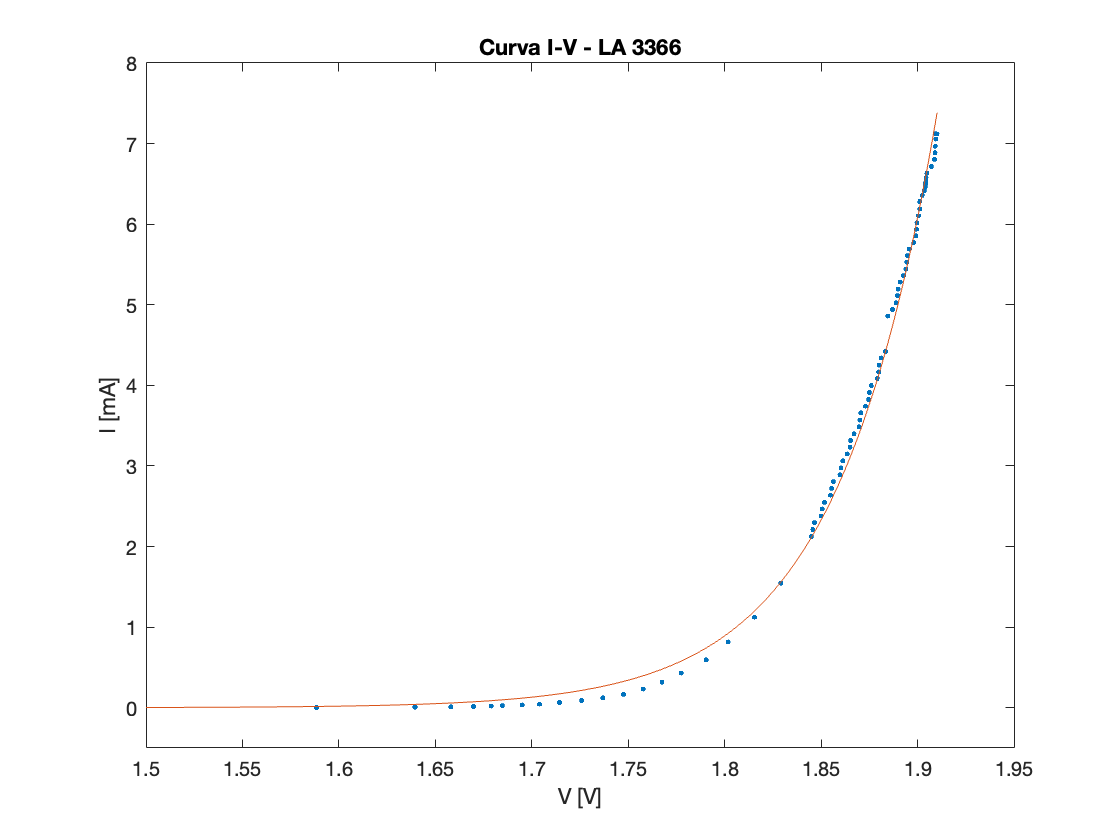

xx=linspace(1.5,max(V), 1000);
yy=(p(1)*(exp(xx*1/eVt*1e3)));
hold on
plot(xx,yy)
hold off
ylim([-0.5, 8])
title('Curva I-V - LA 3366')
ylabel('I [mA]')
xlabel('V [V]')

Risultati del fit: 

- $\eta V_T = 52.1$ mV

- $I_S = (8.82 \pm 0.04) \cdot 10^{-18}$ mA

- 
$$\chi^2 = 16$$


**Misura 2: HLMP C115 - R1 = 330 Ohm**

Anche qui Vs da 0.01 a 8.5 V, fino al regime di saturazione.

R=330*1e-3;
dR=3.3*1e-3;

datamat=readmatrix('Data LAB es 22 2');
V=datamat(:,1);
I=datamat(:,2);


plot(V,I, '.')

dVdig=20*2^(-12);
dV=dVdig*ones(length(V), 1);
Vout=I*R;
dVout=dV;
dI=sqrt((Vout*dR/R^2).^2+(dVout/R).^2);

pin=[4.5e-10]';
eVt=50

eVt = 50

modello = @(p,x)(p(1)*(exp(x*1/eVt*1e3)));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(V, I,modello, pin, 'Weights', dI.^(-2));
%eVT_mV=1/p(2)*1e3
Is=p(1)

Is = 1.5993e-15

dIs=sqrt(COVB(1,1))

dIs = 4.6548e-17


chisq_norm=chi2n

chisq_norm = 550.3919

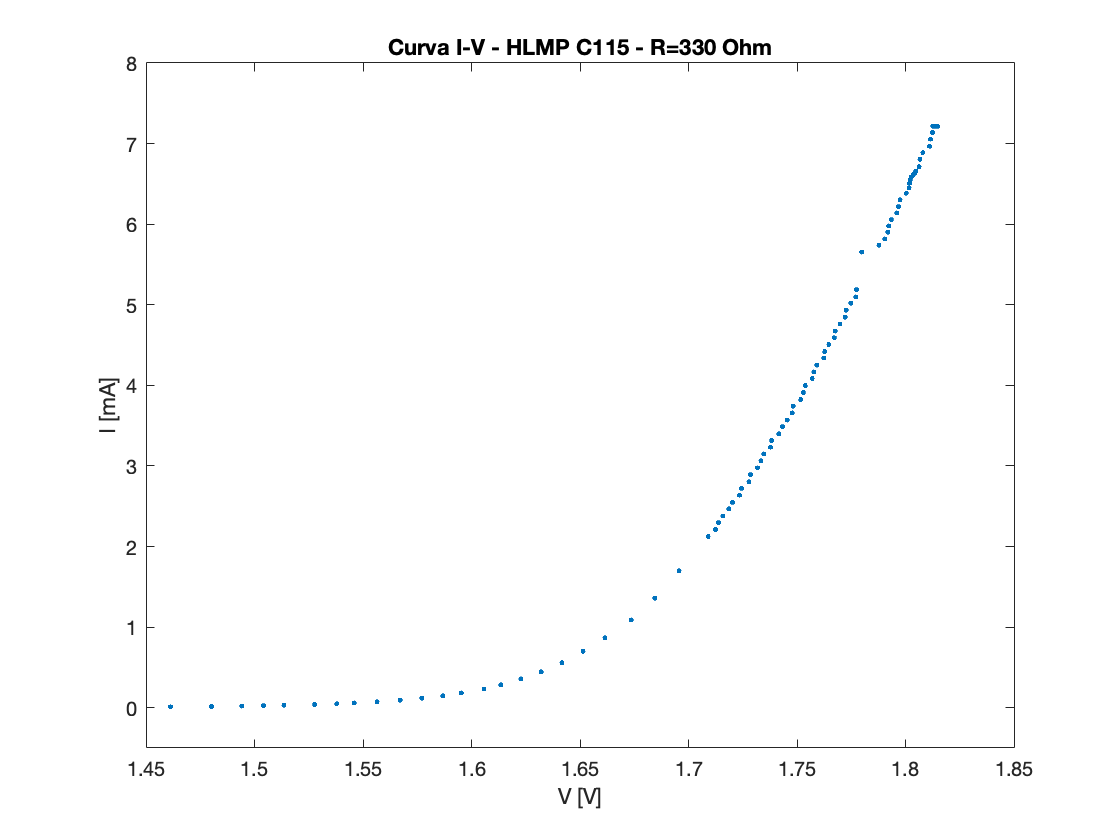

xx=linspace(1.5,max(V), 1000);
yy=(p(1)*(exp(xx*1/eVt*1e3)));
hold on
%plot(xx,yy)
hold off
ylim([-0.5, 8])
title('Curva I-V - HLMP C115 - R=330 Ohm')
ylabel('I [mA]')
xlabel('V [V]')

Risultati del fit: 

- $\eta V_T = 62$ mV

- $I_S = (1.65 \pm 0.03) \cdot 10^{-13}$ mA

- 
$$\chi^2 = 107.4$$


**Misura 3: HLMP C115 -R1=100 Ohm**

Abbiamo impostato Vs da 0.01 a 3 V, in modo da rimanere sotto la corrente di 30 mA, indicata come massima $I_F$ nel datasheet. 

Non abbiamo fatto il fit perché a correnti alte si discosta molto dall'esponenziale che esce dal fit per correnti basse (fino a circa 5 mA).

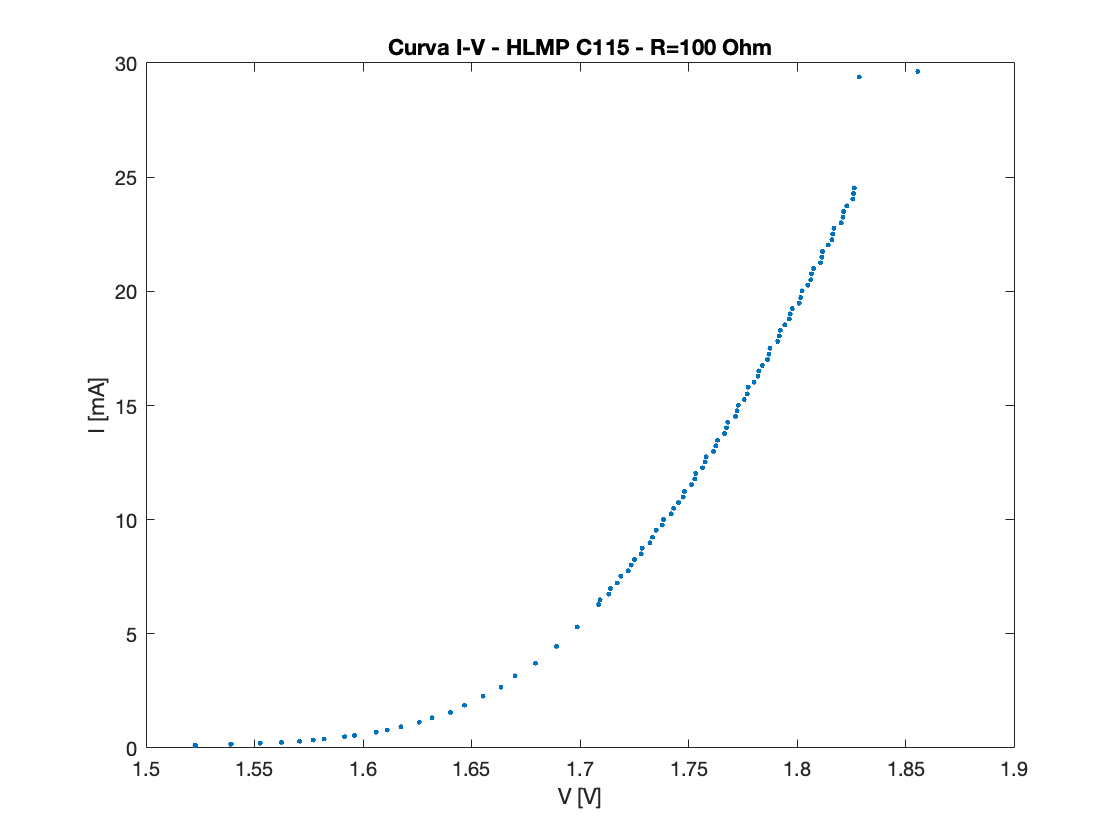

R=100*1e-3;
dR=1*1e-3;
datamat=readmatrix('Data LAB es 22 3');
V=datamat(:,1);
I=datamat(:,2)*10;

plot(V,I, '.')
dVdig=20*2^(-12);
dV=dVdig*ones(length(V), 1);
Vout=I*R;
dVout=dV;
dI=sqrt((Vout*dR/R^2).^2+(dVout/R).^2);

title('Curva I-V - HLMP C115 - R=100 Ohm')
ylabel('I [mA]')
xlabel('V [V]')

**Misura 4: WP 9294 QBC - R1=100 Ohm**

Abbiamo impostato Vs da 0.01 a 3.4 V, in modo da superare di poco la corrente di 30 mA, indicata come massima $I_F$ nel datasheet (al massimo abbiamo raggiunto i 34 mA).

Non abbiamo fatto il fit perché a correnti alte si discosta molto dall'esponenziale che esce dal fit per correnti basse (fino a circa 5 mA)

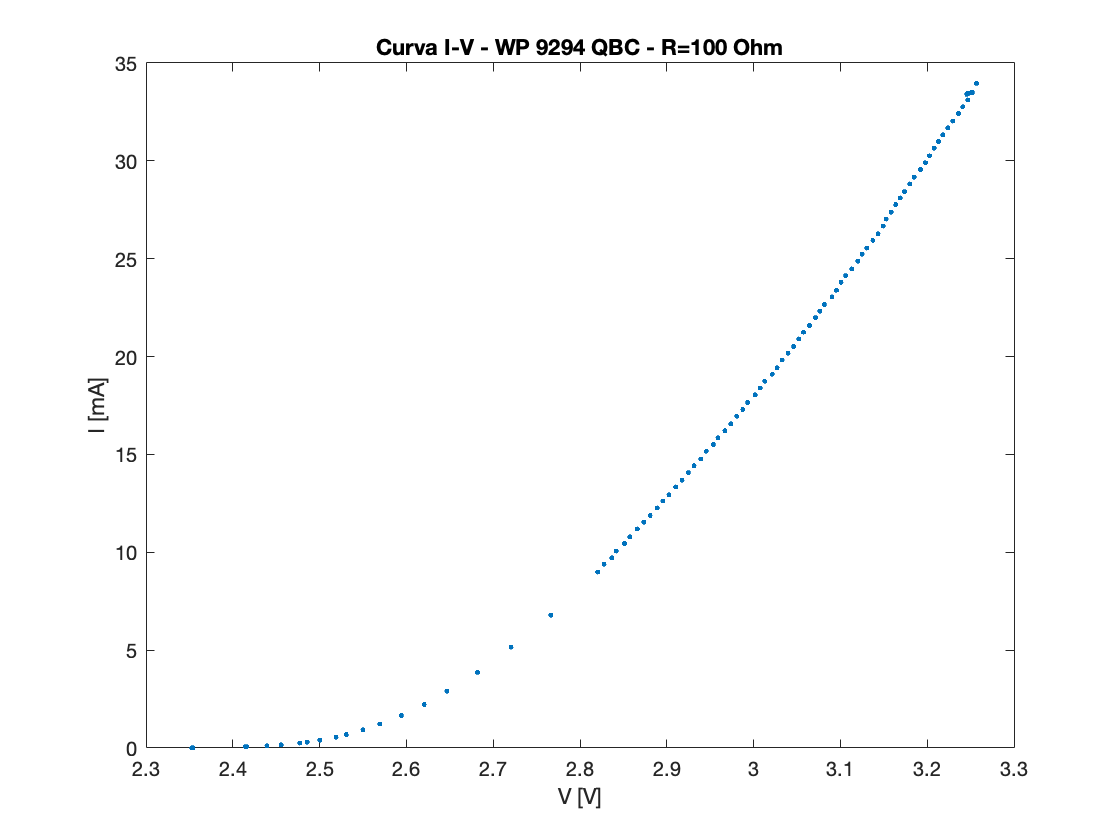

R=100*1e-3;
dR=1*1e-3;
datamat=readmatrix('Data LAB es 22 4');
V=datamat(:,1);
I=datamat(:,2)*10;

plot(V,I, '.')

dVdig=20*2^(-12);
dV=dVdig*ones(length(V), 1);
Vout=I*R;
dVout=dV;
dI=sqrt((Vout*dR/R^2).^2+(dVout/R).^2);

title('Curva I-V - WP 9294 QBC - R=100 Ohm')
ylabel('I [mA]')
xlabel('V [V]')

# Sezione Risultati

## Es. 2 - Tensione di Soglia del MOSFET

Abbiamo stimato come $V_{T} = 2 \pm 0.1 V$ , in accordo con il valore tipico riportato dal datasheet di 2.1 V.

## Es. 9 - Corrente di Drain VS Tensione di Gain per diversi Vds

Riportiamo le tre acquisizioni fatte in regime di saturazione in un unico grafico, dal quale si può confrontare l'andamento.

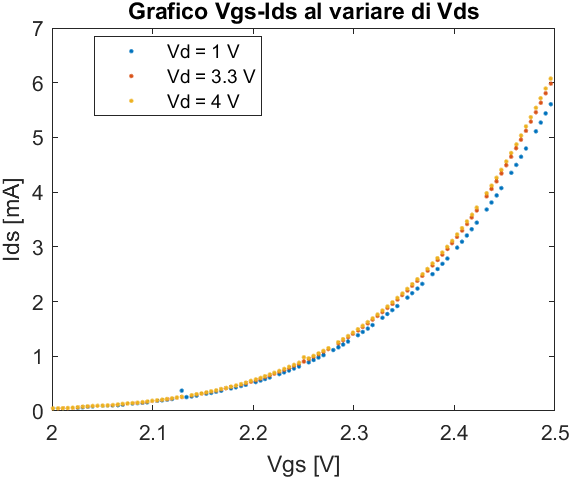

L'andamento è simile, possiamo quindi affermare di essere in regime di saturazione per tutte e tre le acquisizioni. Inoltre si nota che con l'aumentare di Vds, aumenta la pendenza della curva, che è quello che ci aspettavamo considerando l'andamento della transconduttanza (es. successivo).

Riportiamo lo stesso grafico, ma con le misure effettuate con il FET J105:

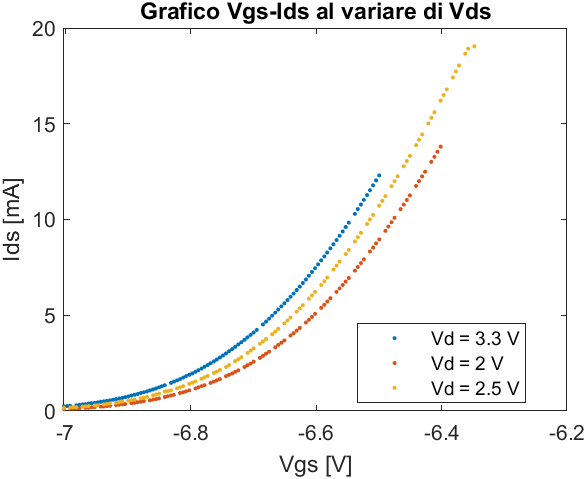

L'andamento è analogo al quello del MOSFET BS170, anche se Vt è negativa in questo caso.

## Es. 10 - Misura della transconduttanza

Eseguiti i fit sulle acquisizioni riportare sopra, abbiamo estrapolato fino a Vds = 10 V per valutarne meglio l'andamento:

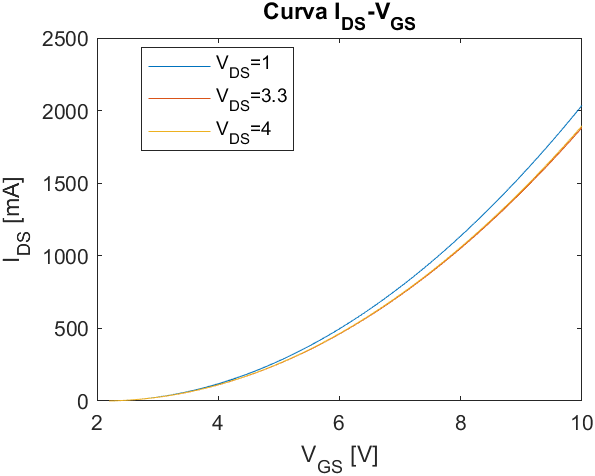

Dai fit si ottiene che per Vds = 1 V la pendenza della curva è maggiore rispetto agli altri due voltaggi, il che è in disaccordo con il risultato che ci aspettavamo. Dubitando quindi della bontà del fit, abbiamo considerato solo le altre due misure per avere una misura della transconduttanza.

La formula per la tranconduttanza è: $g_m=p_1(V_{GS}-V_T)=2\sqrt{I_{DS}\frac{K_n(1+\lambda V_{DS})}{2} }$

Dalle due acquisizioni selezionate abbiamo ricavato $K_n=58.31 \pm 0.04\,\,\, mA/V^2$ e $\lambda = (9.1 \pm 0.2) \cdot 10^{-3} \,\,\,V^{-1}$, da cui $g_m=159 \pm 4 \,\, mS$ calcolata a Vds = 10 V e Ids = 200 mA.

Con questi valori il datasheet riporta $g_m = 320 mS$.

## Es. 12 - Misura della transconduttanza pt.2

Lavorando a correnti più alte grazie all'utilizzo del generatore e all'OpAmp OP37, abbiamo preso due misure per provare a misurare meglio la transconduttanza.

A Vds = 10 V e Ids = 200 m A, la misura è: $g_m=244\pm75\,\,\, mS$, che è compatibile con il valore atteso di $g_m = 320 mS$.

## Es. 15 - Simulazione con TINA con R2

**Dipendenza della corrente ai capi di R1 da Vs**

Ci aspettiamo che nella zona lineare $I=\frac{ V_S}{R_1}$

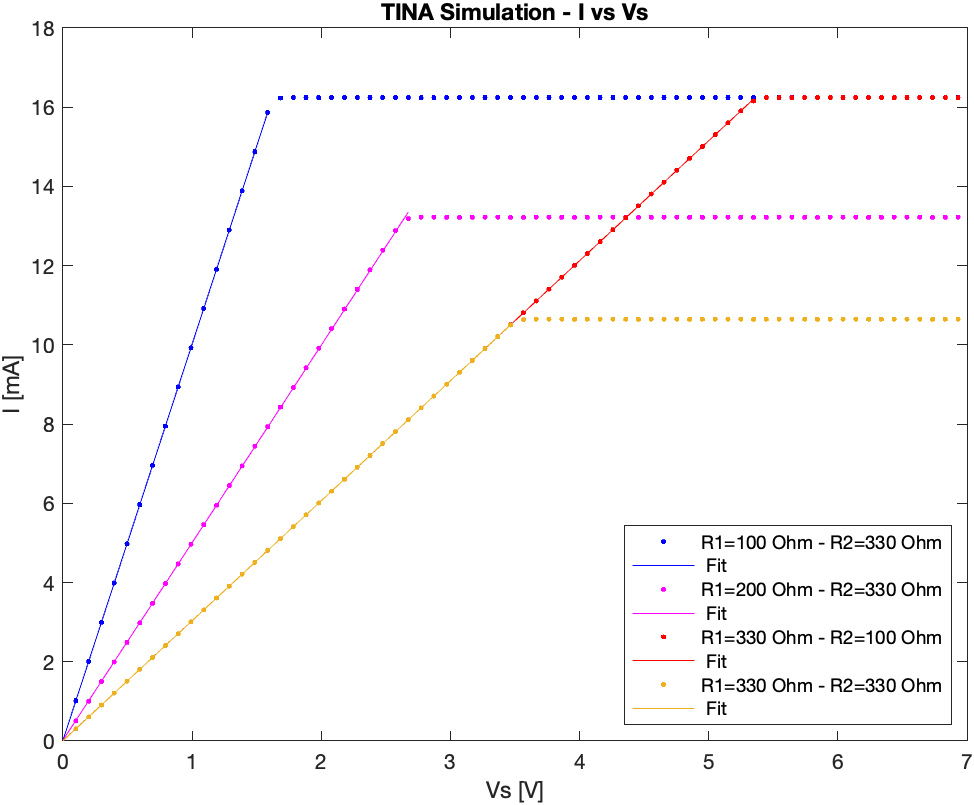

Si vede dai vari fit che il coefficiente angolare è esattamente 1/R1 come atteso, mentre la tensione Vs a cui inizia la saturazione, e di conseguenza la corrente per cui si ha saturazione, aumenta al diminuire del rapporto ${R_2}{/R_1}$. 

Infatti, $V_{Drain} = 12$ V costante,  $V_{Source} = V_S \left(1+{R_2}/{R_1}\right)$, mentre $V_{Gate}$ aumenta linearmente con $V_S$, quindi $V_{GS} $ sale sopra la soglia della saturazione per valori più grandi di $V_S$ al diminuire di $R_2 / R_1$. 

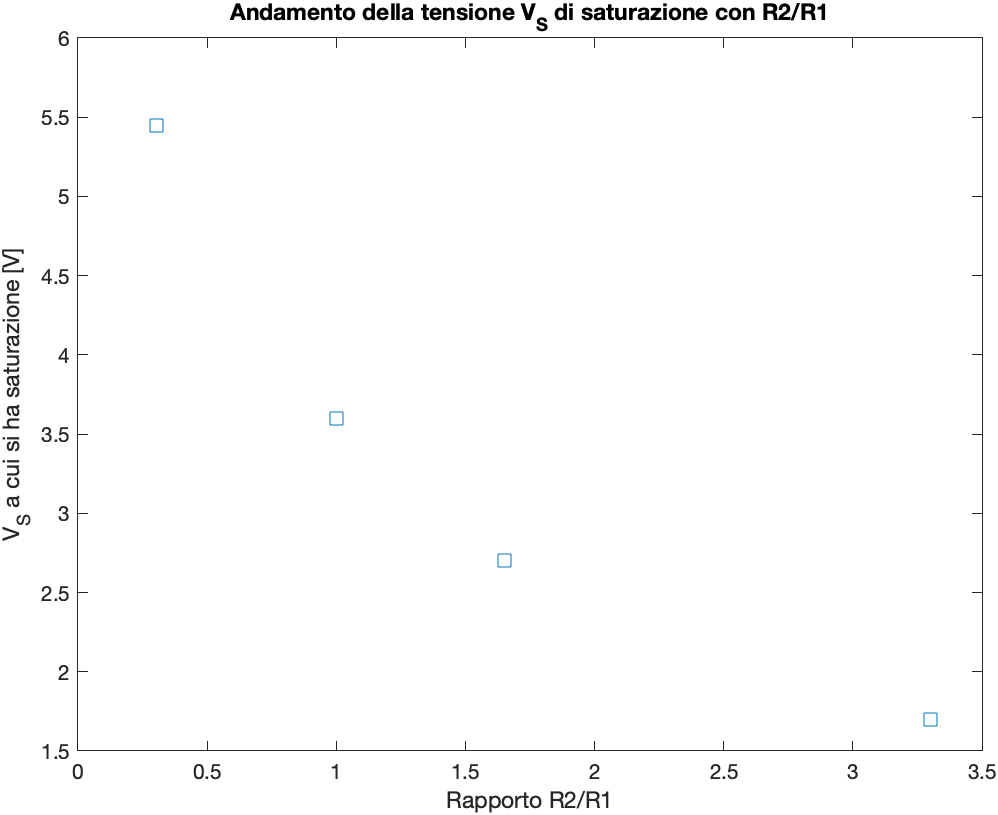

**Dipendenza della corrente ai capi di R1 da R1**

Ci aspettiamo che nella zona lineare $I=\frac{ V_S}{R_1}$

Abbiamo variato R1 tra 10 Ohm e 1 kOhm e fissato Vs a 5 V e R2 a 330 Ohm

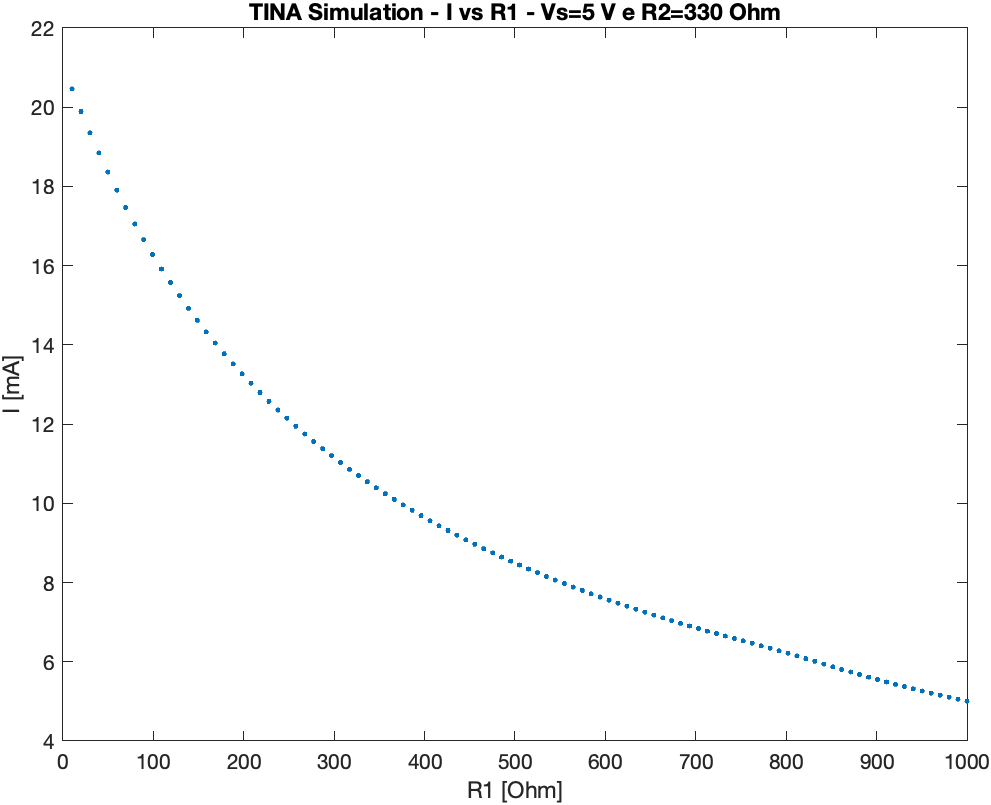

Si vede che la corrente diminuisce all'aumentare di R1, ma l'andamento non è del tipo $1/R_1$.

**Dipendenza di Vsource da R2**

Andamento atteso: 

$V_{Source} = V_S \left(1+R_2/R_1\right)$ nel regime lineare, finché non si arriva alla saturazione. 

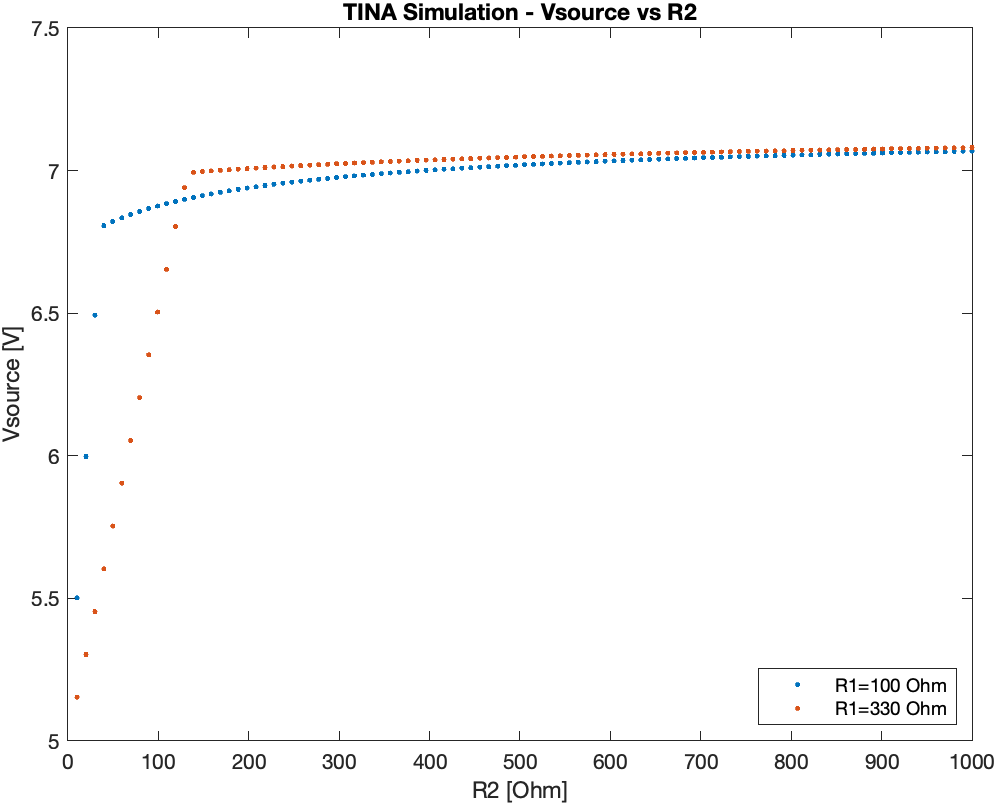

Si vede che $V_{Source}$ aumenta linearmente con $R_2$ finché non arriva a 7 V, poi si ferma perché il transistor è arrivato in saturazione.

$V_{Gate}$ è costante perché $V_S$ è costante e $V_{Drain}$ è fissa a 12 V, quindi l'unica tensione variabile è $V_{Source}$ e si arriva in saturazione quando $V_{DS}$ è sufficientemente alta rispetto a $V_{GS}$. Questo passaggio di regime si ha per $V_{Source} = 7$ V e questo valore non dipende dalle resistenze usate. 

**Dipendenza  della corrente ai capi di R1 da R2**

Abbiamo variato R2 tra 10 Ohm e 1 kOhm e simulato per diversi valori di R1 e impostando Vs a 5 V.

$V_{source}-V_S = R_2 I$ quindi $I$ è inversamente proporzionale a $R_2$, mentre $V_{source}$ cresce linearmente con $R_2$ e con $V_S$. 

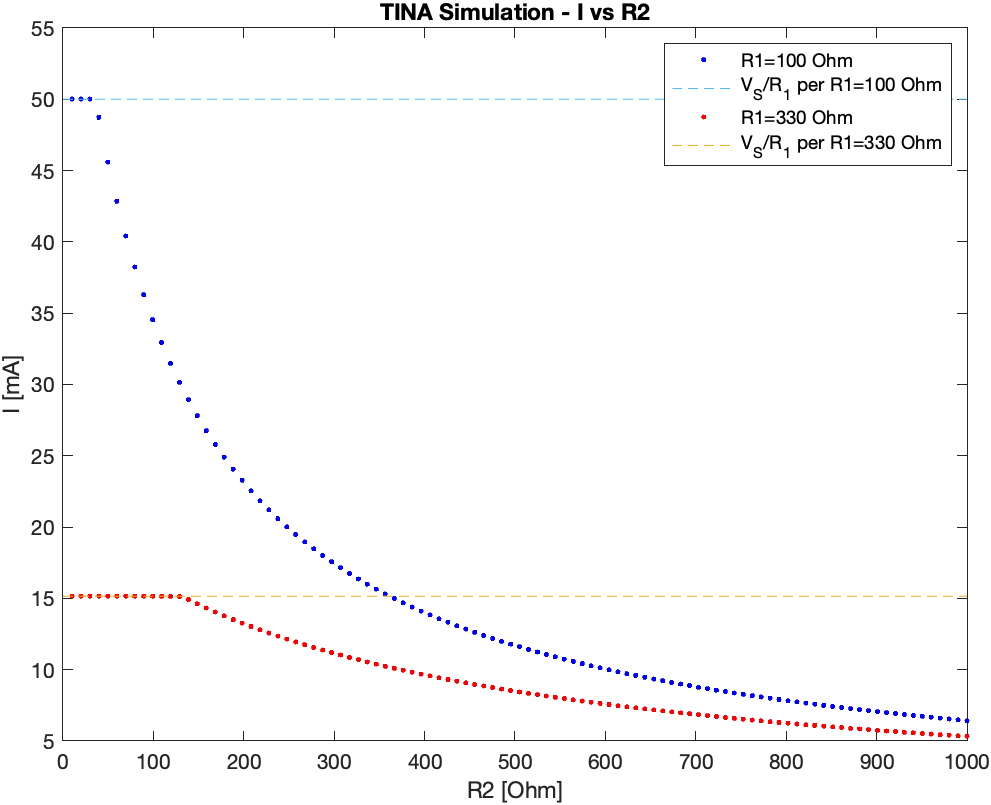

Se si usa $R_1=330$ Ohm, la corrente non supera mai 15 mA se si lavora con una tensione massima $V_S$ di 5 V.